# Eksamenssæt May 2017 Katrine 

## Q1 - xx

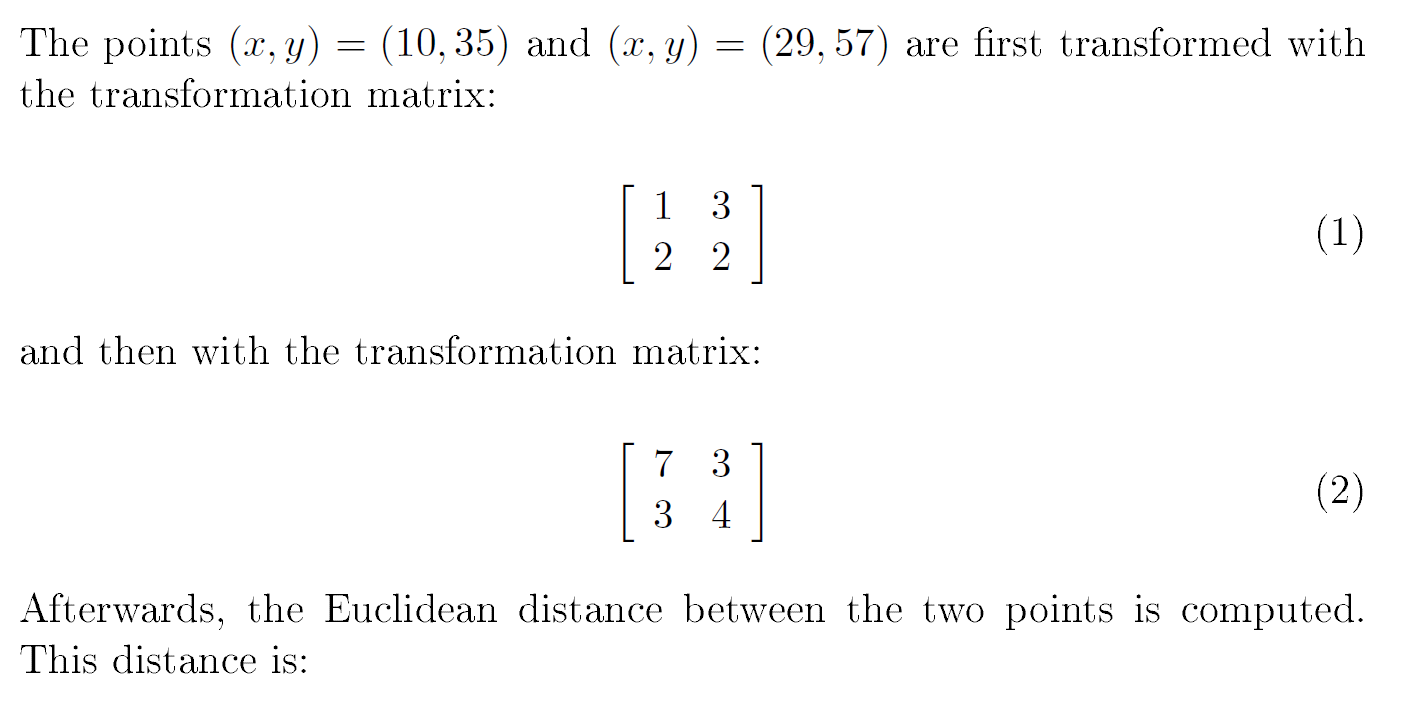

Keywords: transformation matrix. Euclidean distance between two points. 

close all; clear; clc;
point1 = [10;35];
point2 = [29;57];

% first trandformation
trans1 = [1, 3; 2, 2];
t1p1 = trans1 *point1

t1p1 =    115
    90


t1p2 = trans1 *point2

t1p2 =    200
   172



% second trandformation 
trans2 = [7, 3; 3, 4];
t2p1 = trans2 * t1p1

t2p1 =         1075
         705


t2p2 = trans2 * t1p2

t2p2 =         1916
        1288



%euclidean_distance = sqrt((t2p1-t2p2)^2)
format bank
euclidean_distance = sqrt((1075-1916)^2 + (705-1288)^2)

res =        1023.31


Svar: 1 = 1023

## Q2 - true positives

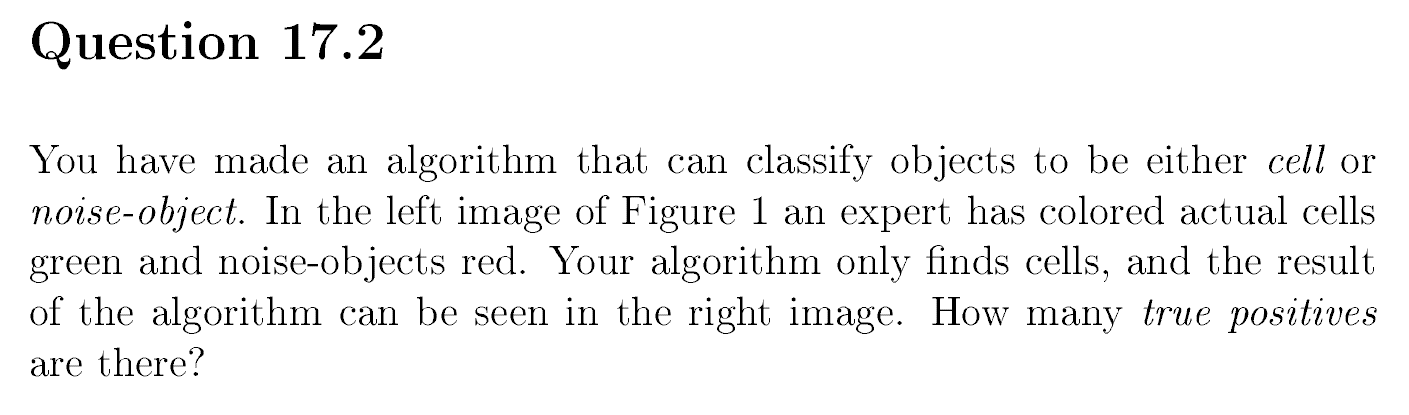

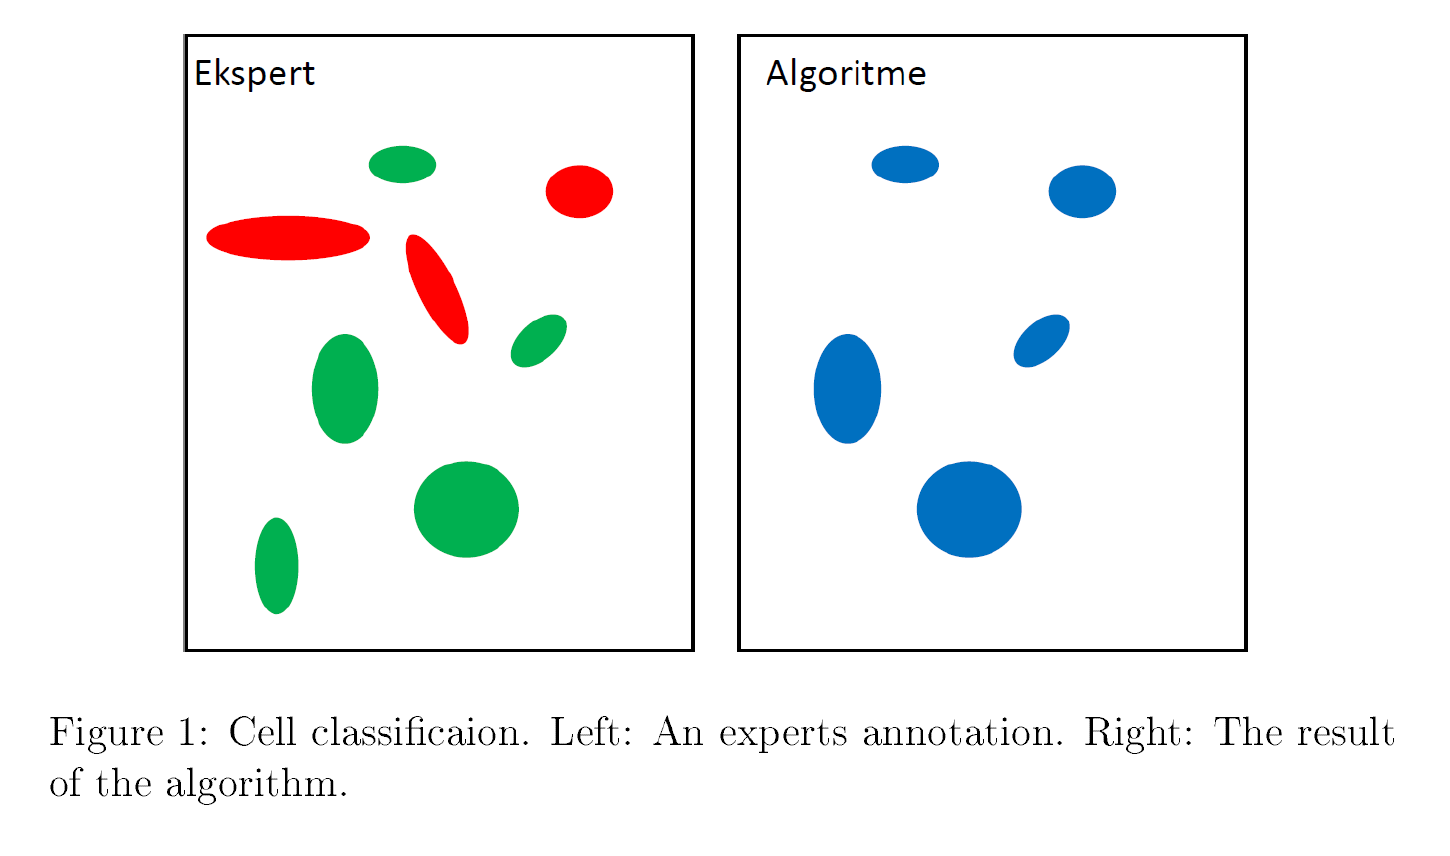

close all; clear; clc;
% Der er 4 true positives

Svar: 3 = 4

## Q4 - optimal path

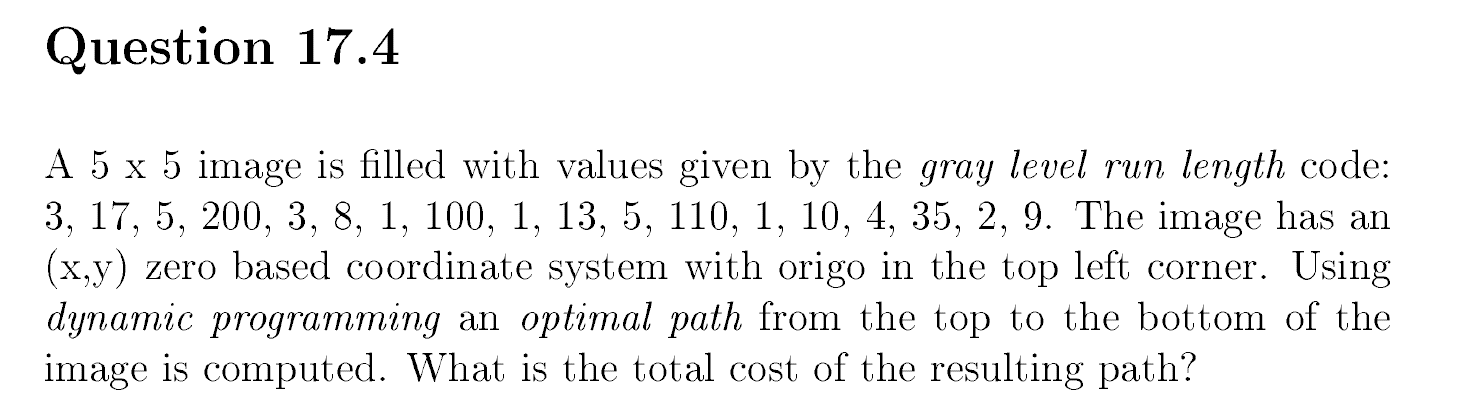

close all; clear; clc;
I = [17, 17, 17, 200, 200, 200, 200, 200, 8, 8, 8, 100, 13, 110, 110, 110, 110, 110, 10, 35, 35, 35, 35, 9, 9];
I = reshape(I, [5,5])';
% optimal path is calculated
cost = exam_funcs.OptPath(I);
cost

cost =          57.00


SVar: 5=57

## Q5- 

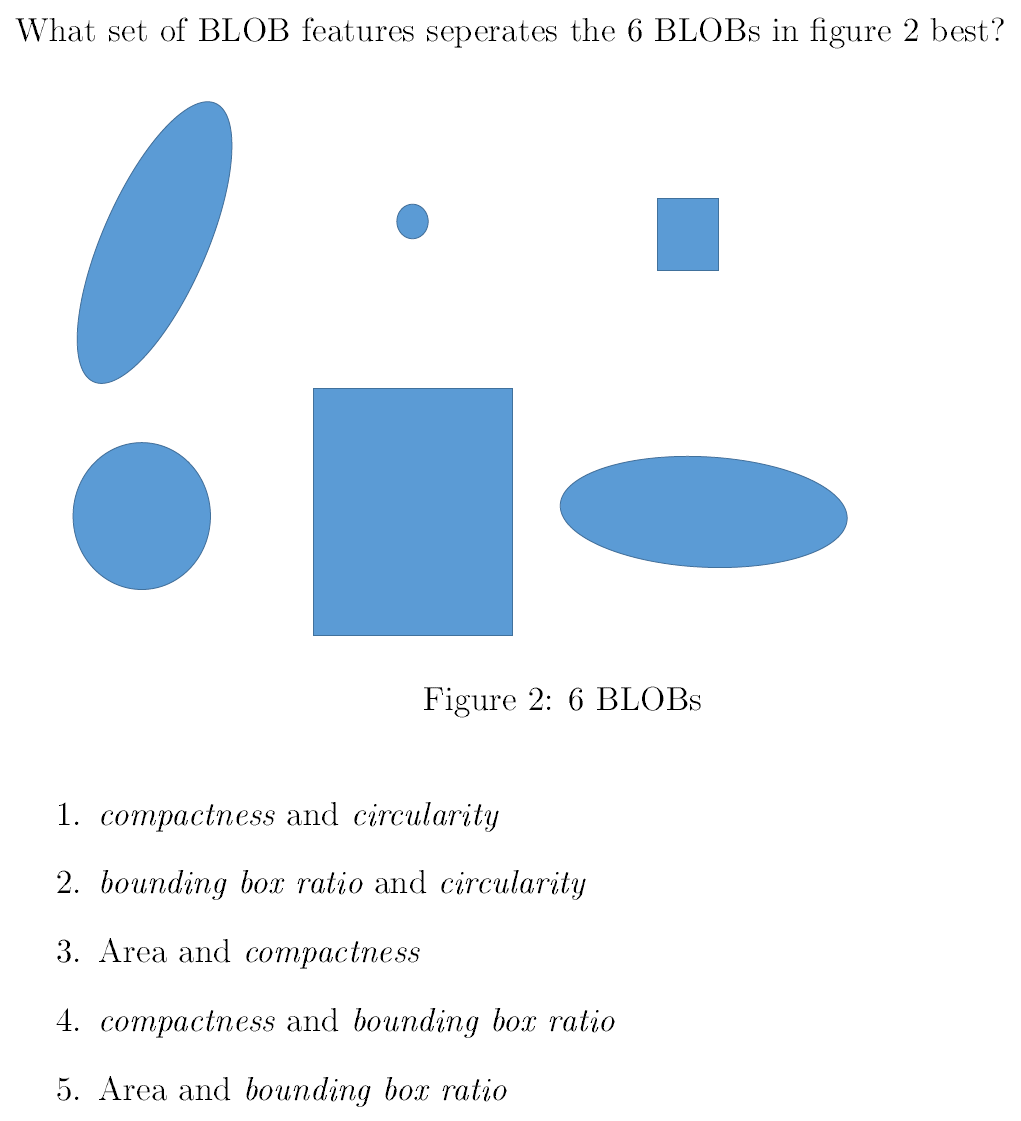

Svaret: 5 = bounding box ratio and area

## Q6 - Gamma and prewitt

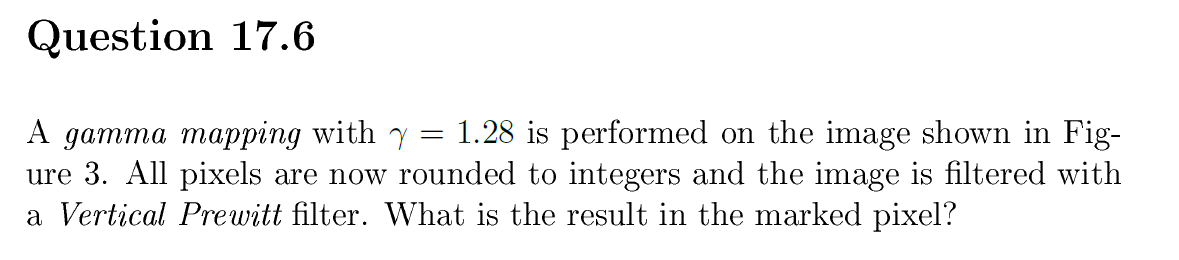

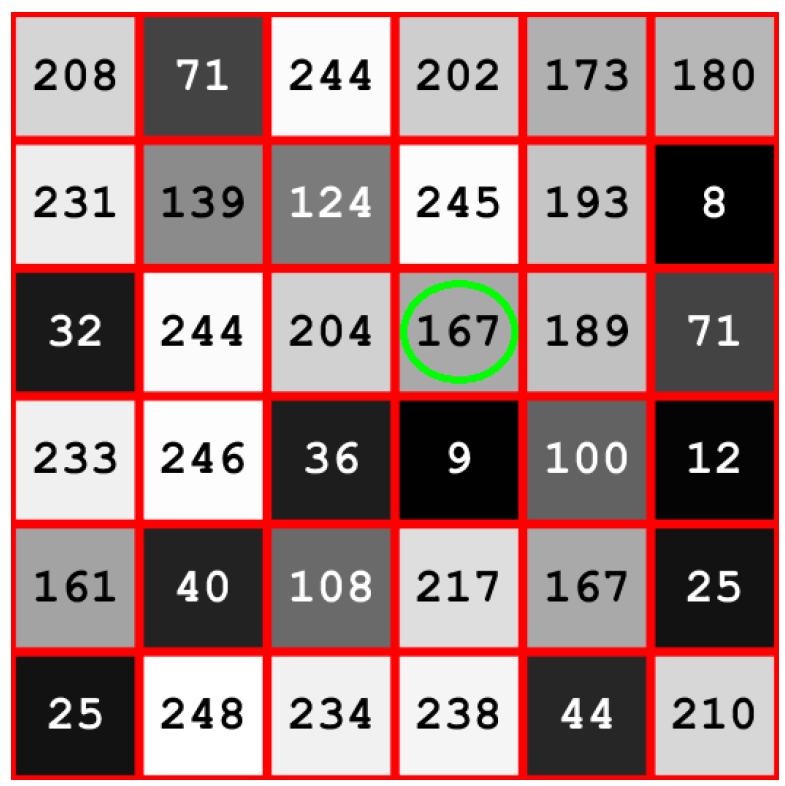

close all; clear; clc;
I = [208, 71, 244, 202, 173, 180;
231, 139, 124, 245, 193, 8;
32, 244, 204, 167, 189, 71;
233, 246, 36, 9, 100, 12;
161, 40, 108, 217, 167, 25;
25, 248, 234, 238, 44, 210];

% Gamma transformation
im_gamma_mapped = exam_funcs.GammaMap(I,1.28);
im_gamma_mapped = round(im_gamma_mapped);

% Prewitt filter
prewitt_filter = [-1,0,1;-1,0,1;-1,0,1]; % vertical
first = imfilter(im_gamma_mapped,prewitt_filter)

first =         167.00        -79.00        264.00         -8.00       -265.00       -334.00
        408.00         95.00        171.00        -26.00       -363.00       -508.00
        602.00       -156.00       -208.00        116.00       -336.00       -430.00
        509.00        -89.00       -150.00        101.00       -291.00       -399.00
        514.00        -48.00        -70.00        -82.00       -227.00       -252.00
        270.00        158.00        170.00       -138.00       -228.00       -175.00


first(3,4)

ans =         116.00


% svaret er 116

Svar: 2 = 116

## Q7

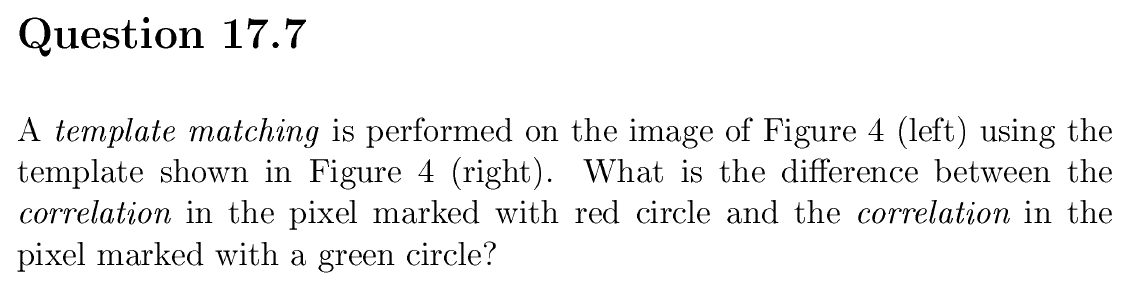

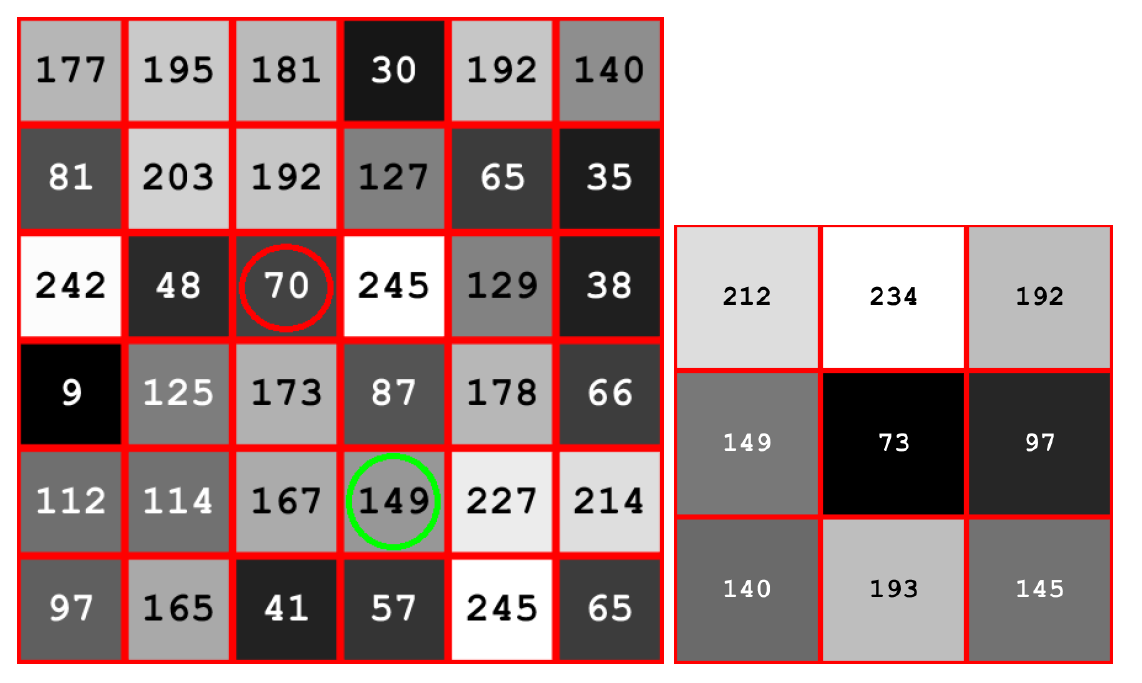

close all; clear; clc;
% template matching
I = [177, 195, 181, 30, 192, 140;
81, 203, 192, 127, 65, 35;
242, 48, 70, 245, 129, 38;
9, 125, 173, 87, 178, 66;
112, 114, 167, 149, 227, 214;
97, 165, 41, 57, 245, 65];

template = [212, 234, 192; 149, 73, 97; 140, 193, 145];

I_red = I(2:4,2:4);
I_green = I(4:6,3:5);

corr_2d_red = sum(I_red.*template, "all")  %ikke normaliseret 

corr_2d_red =      211879.00


corr_2d_green = sum(I_green.*template, "all") 

corr_2d_green =      201255.00


diff = corr_2d_red - corr_2d_green

diff =       10624.00


Svaret er 2: 10624

## Q8

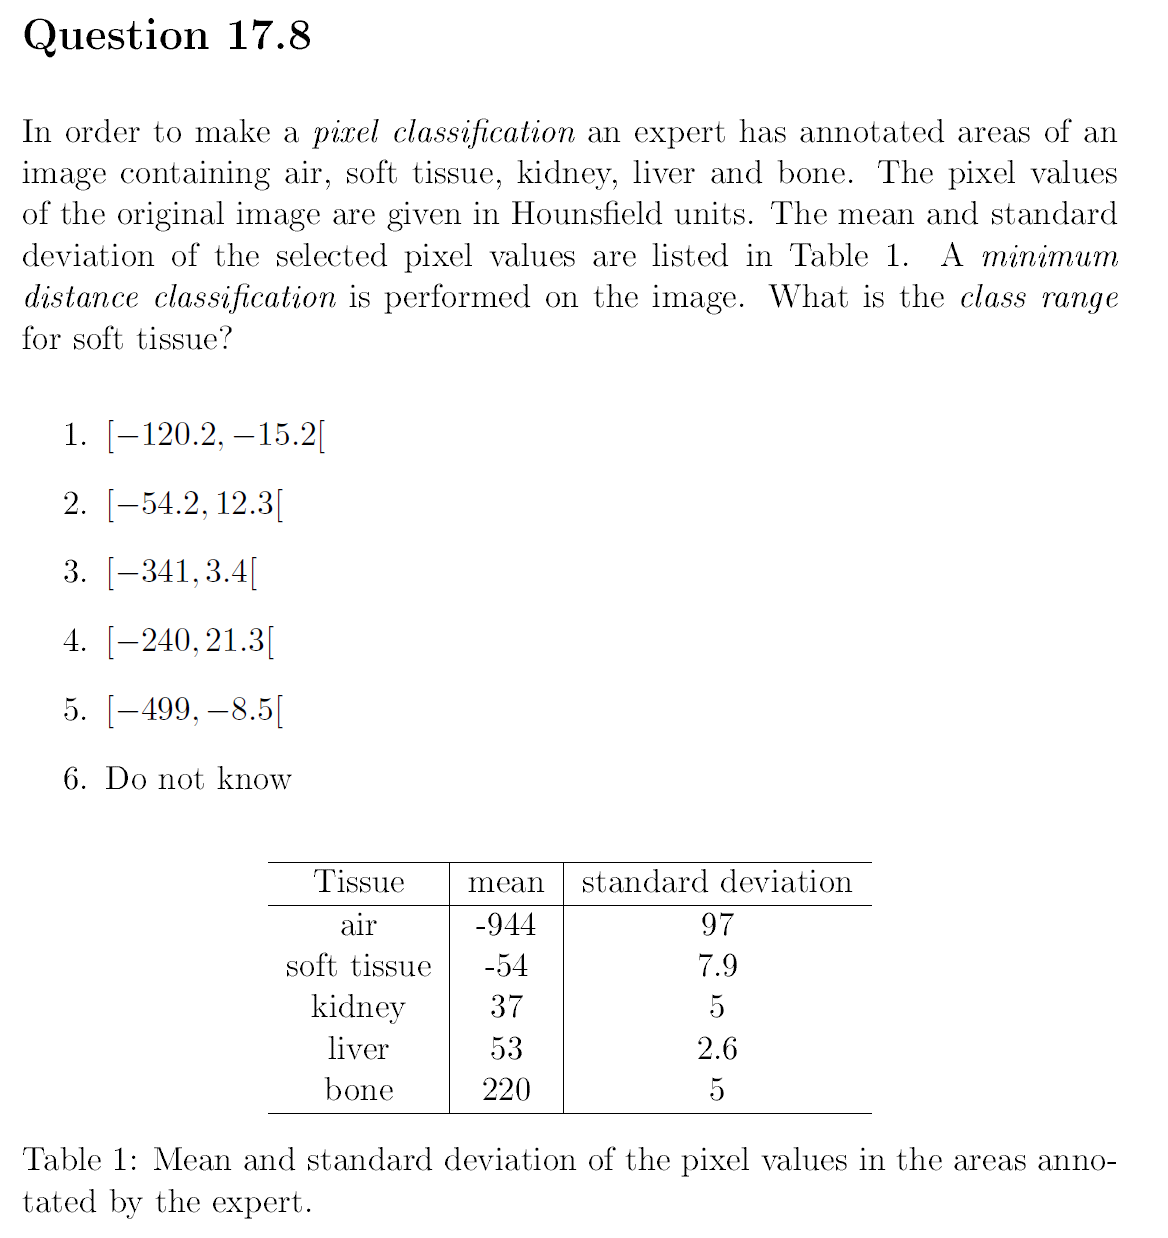

close all; clear; clc;
% minimum distance classifier

%minimum distance classifier and finding the class range 
[(-54+37)/2, (-54+(-944))/2]

ans =          -8.50       -499.00


Svaret er 5. (-499, -8.5)

## Q10 - normalized cross correlation

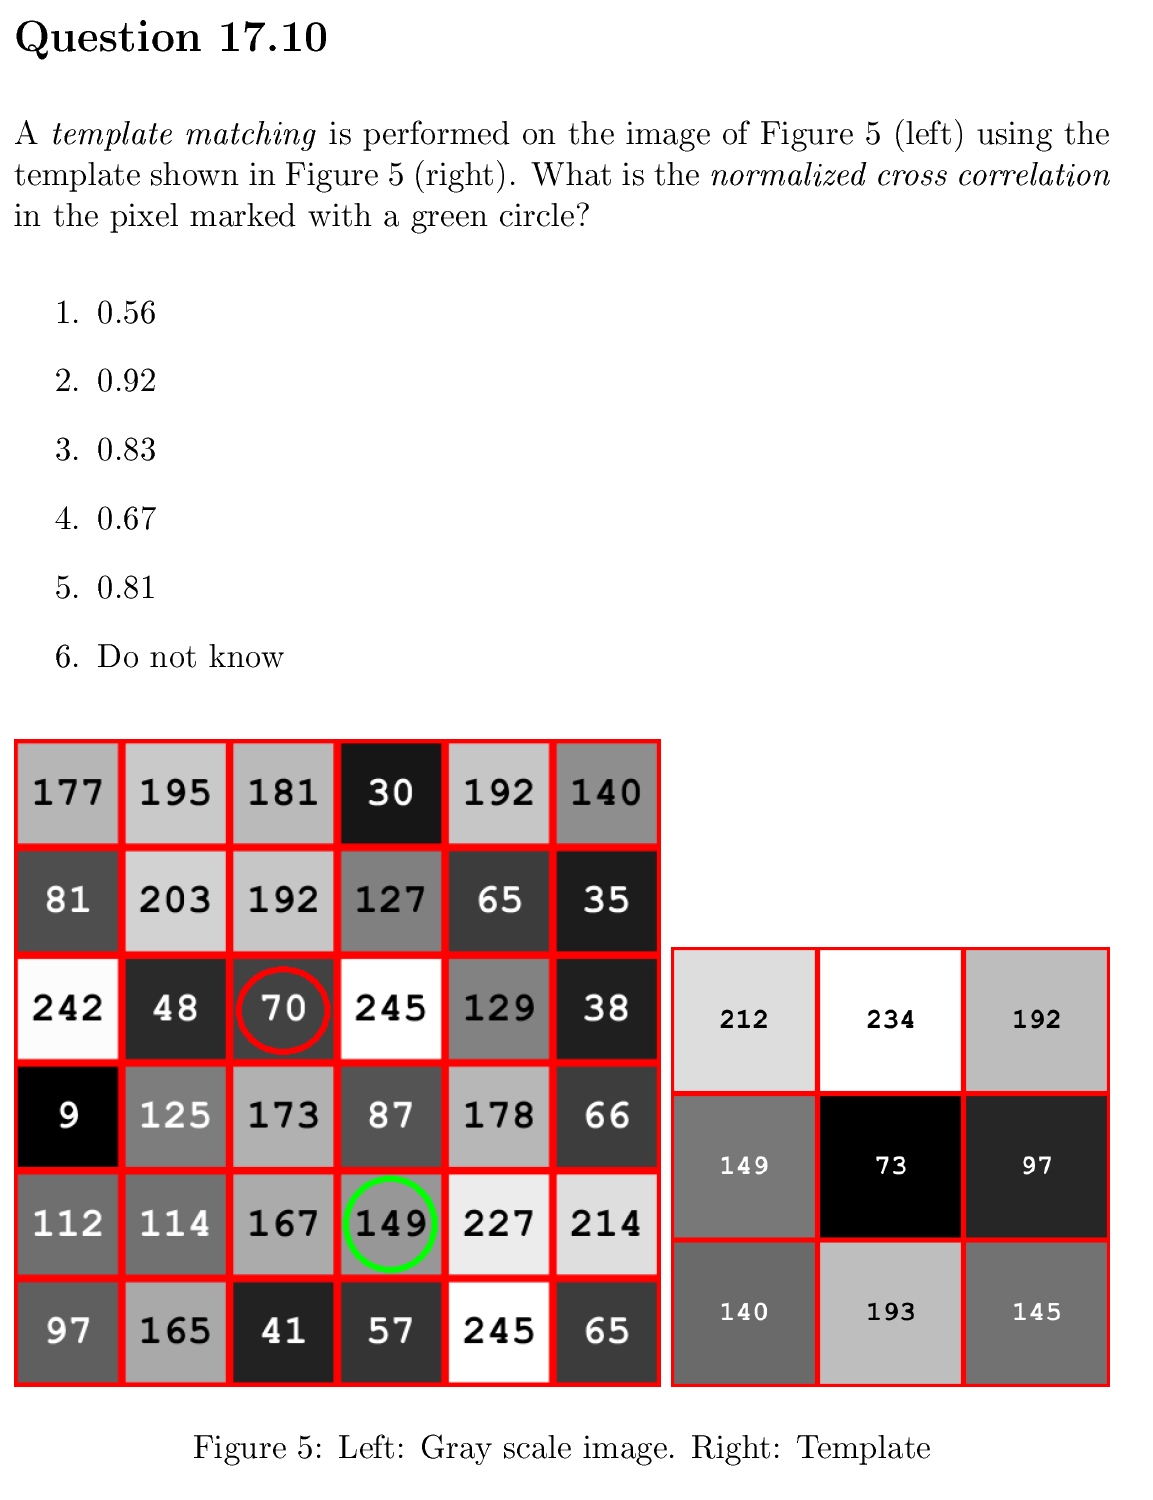

close all; clear; clc;
% template matching
I = [177, 195, 181, 30, 192, 140;
81, 203, 192, 127, 65, 35;
242, 48, 70, 245, 129, 38;
9, 125, 173, 87, 178, 66;
112, 114, 167, 149, 227, 214;
97, 165, 41, 57, 245, 65];

template = [212, 234, 192; 149, 73, 97; 140, 193, 145];

I_red = I(2:4,2:4);
I_green = I(4:6,3:5);

% cross correlation 
corr_2d_green = exam_funcs.NormCrossCorr2D(I_green, template) 

corr_2d_green =           0.83


Svaret er 3: 0.83

## Q11 - BLOB 8-connectivity

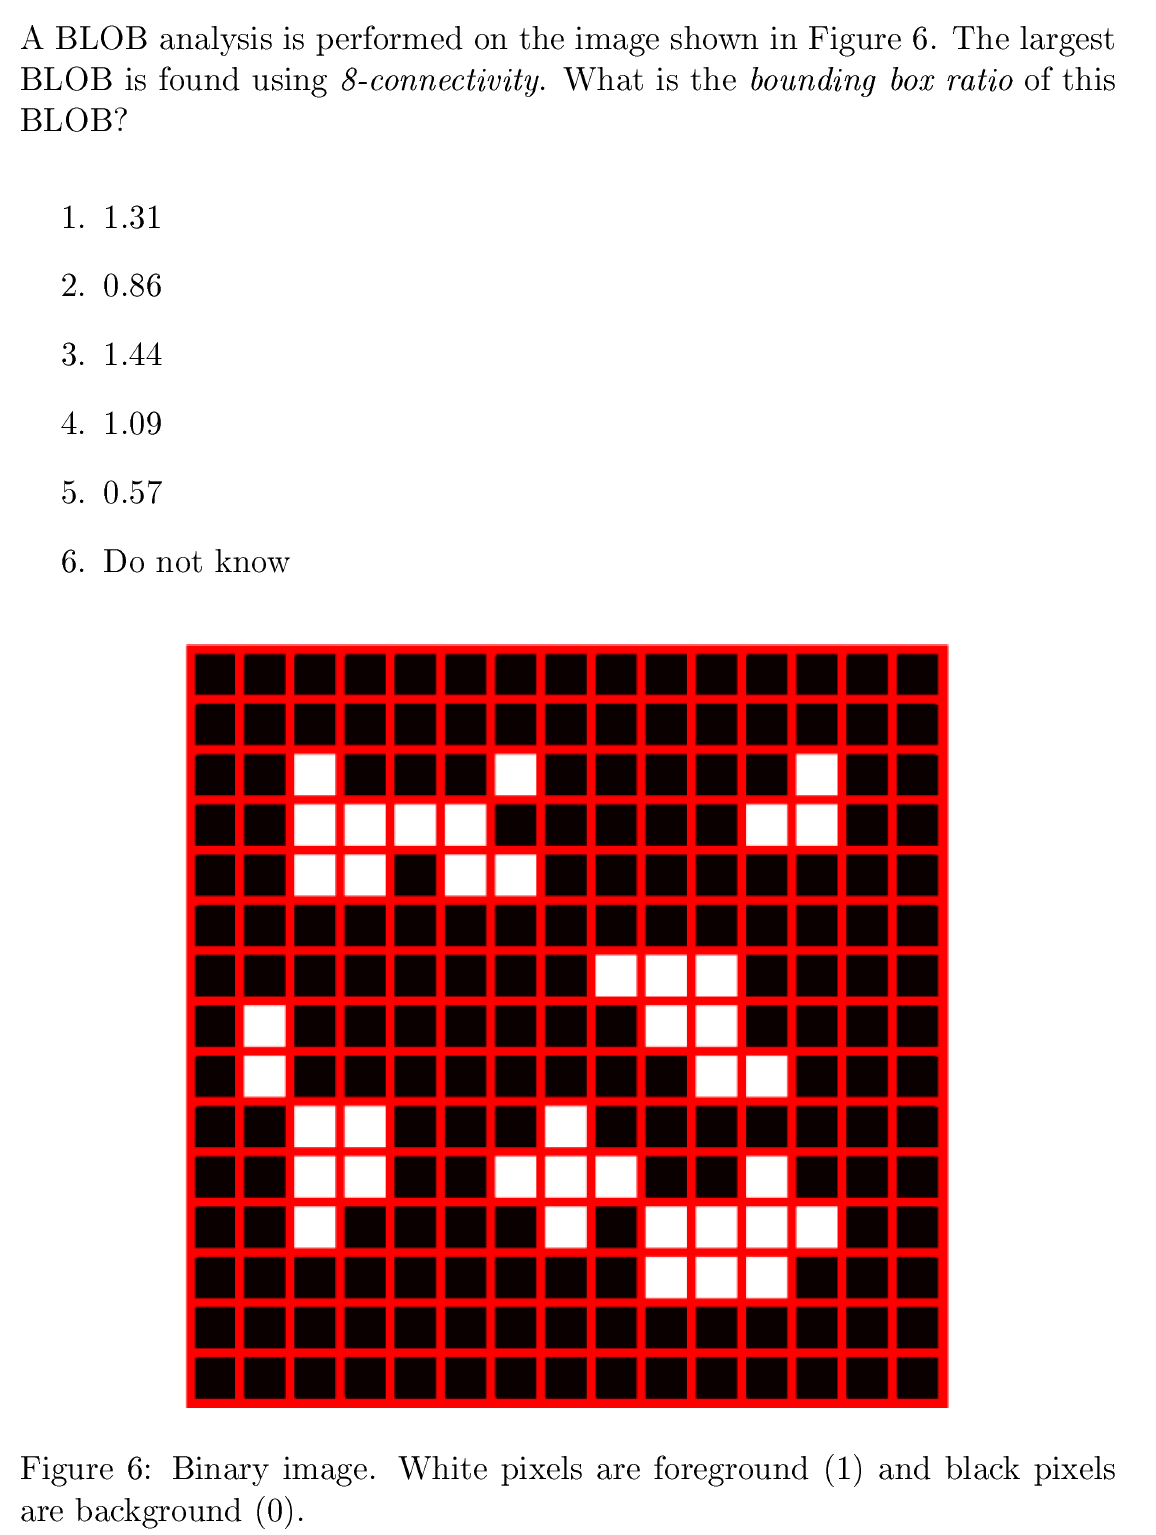

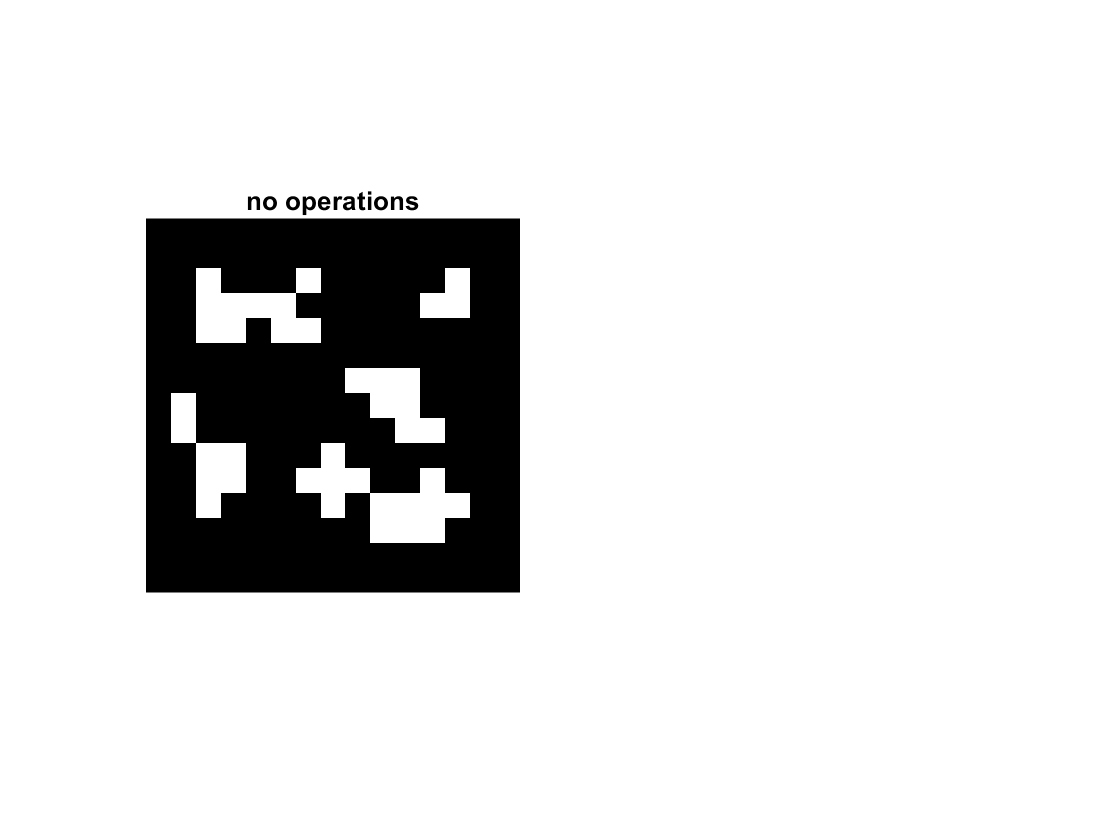

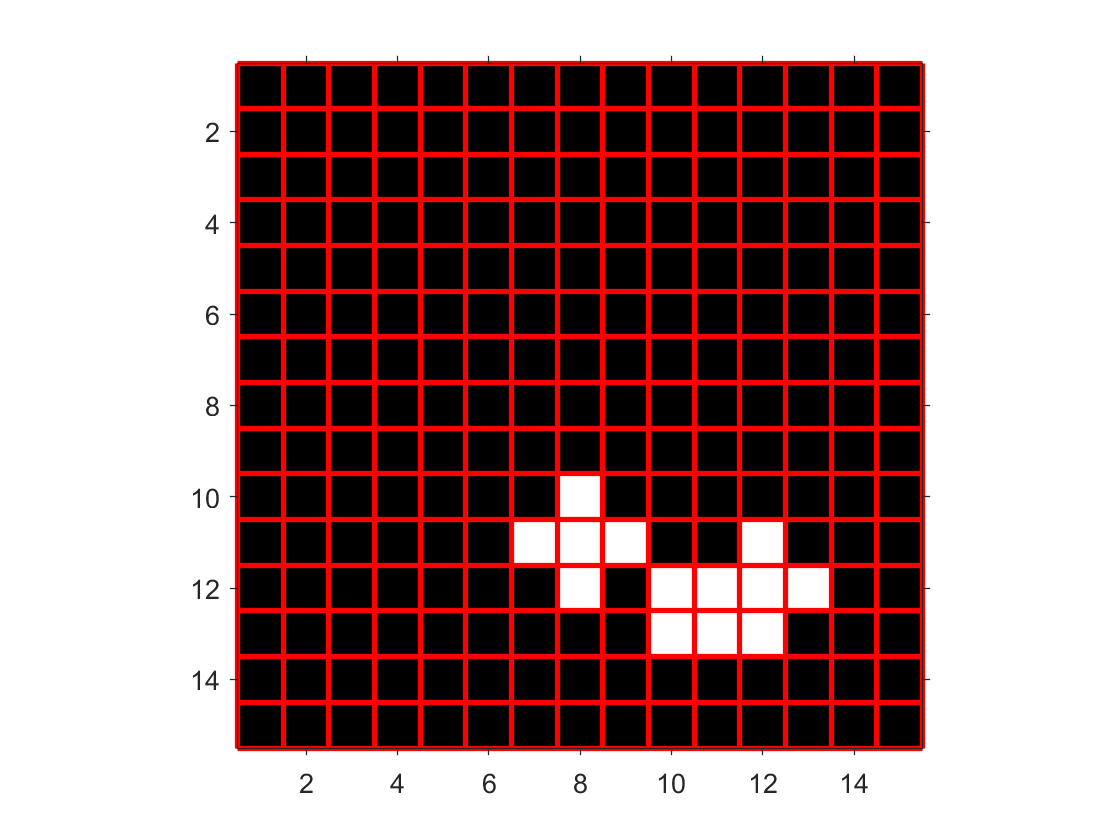

close all; clear; clc;

I = zeros(15);
I(3, [3,7,13])=1;
I(4, [3:6, 12:13])=1;
I(5, [3:4, 6:7])=1;
I(7, 9:11)=1;
I(8, [2, 10:11])=1;
I(9, [2, 11:12])=1;
I(10, [3:4, 8])=1;
I(11, [3:4, 7:9, 12])=1;
I(12, [3, 8, 10:13])=1;
I(13, 10:12)=1;
figure;
subplot(1,2,1)
imshow(I, 'InitialMagnification','fit')
title("no operations")

% assign labels using 8-connectivity
bw = bwlabel(I, 8);
stats8 = regionprops(bw, "all")

stats8 = 5×1 struct array with fields:
    Area
    Centroid
    BoundingBox
    SubarrayIdx
    MajorAxisLength
    MinorAxisLength
    Eccentricity
    Orientation
    ConvexHull
    ConvexImage
    ConvexArea
    Circularity
    Image
    FilledImage
    FilledArea
    EulerNumber
    Extrema
    EquivDiameter
    Solidity
    Extent
    PixelIdxList
    PixelList
    Perimeter
    PerimeterOld
    MaxFeretDiameter
    MaxFeretAngle
    MaxFeretCoordinates
    MinFeretDiameter
    MinFeretAngle
    MinFeretCoordinates



% bounding box ratio
% stats for largest blob
[area_max, idx] = max([stats8.Area]);
[H, W] = size(stats8(idx).FilledImage);
%bounding box ratio
BBR_max = H/W

BBR_max = 0.5714

Svaret er 5 = 0.57

## Q12

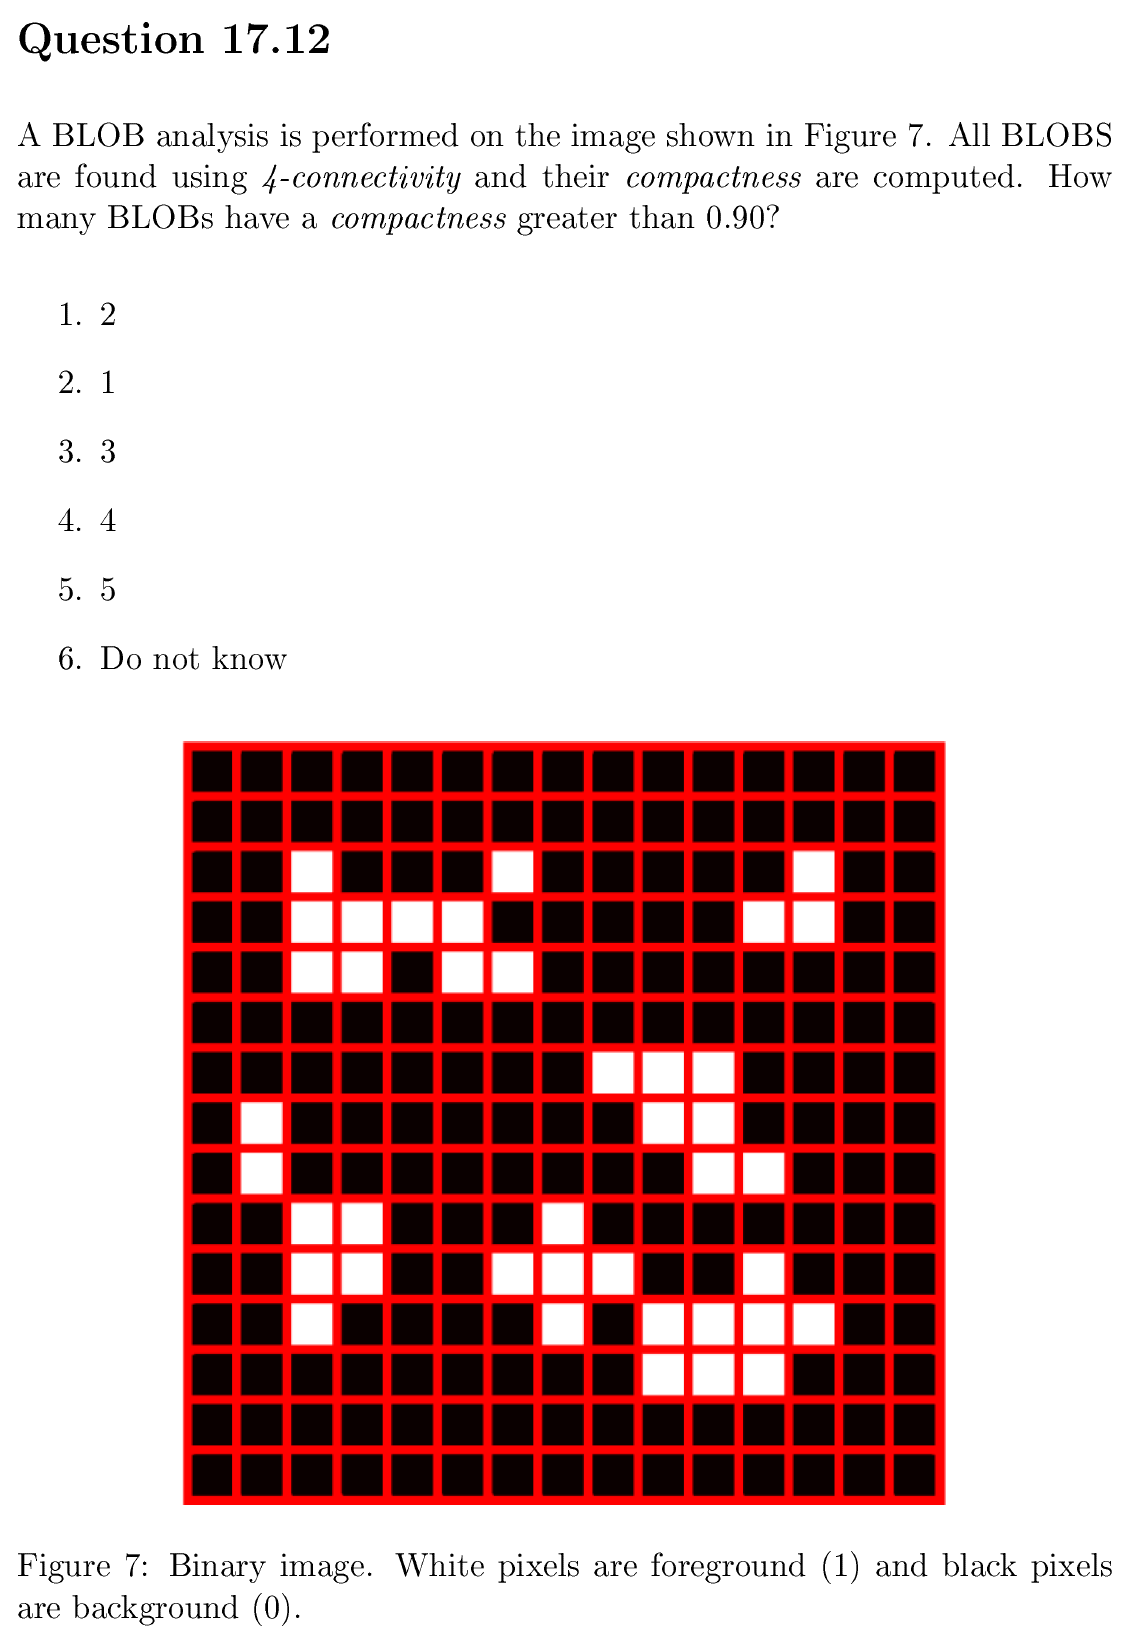

close all; clear; clc;

I = zeros(15);
I(3, [3,7,13])=1;
I(4, [3:6, 12:13])=1;
I(5, [3:4, 6:7])=1;
I(7, 9:11)=1;
I(8, [2, 10:11])=1;
I(9, [2, 11:12])=1;
I(10, [3:4, 8])=1;
I(11, [3:4, 7:9, 12])=1;
I(12, [3, 8, 10:13])=1;
I(13, 10:12)=1;
figure;
subplot(1,2,1)
imshow(I, 'InitialMagnification','fit')
title("no operations")


% now BLOB 
im_blob = bwconncomp(I, 4)

im_blob = struct with fields:
    Connectivity: 4
       ImageSize: [15 15]
      NumObjects: 8
    PixelIdxList: {[2×1 double]  [9×1 double]  [5×1 double]  [93]  [5×1 double]  [7×1 double]  [8×1 double]  [3×1 double]}



compactness = regionprops(im_blob,"Extent") 

compactness = 8×1 struct array with fields:
    Extent



%Der er altså 2, der har compactness større end 0.9


Svaret er 1: 2

## Q13

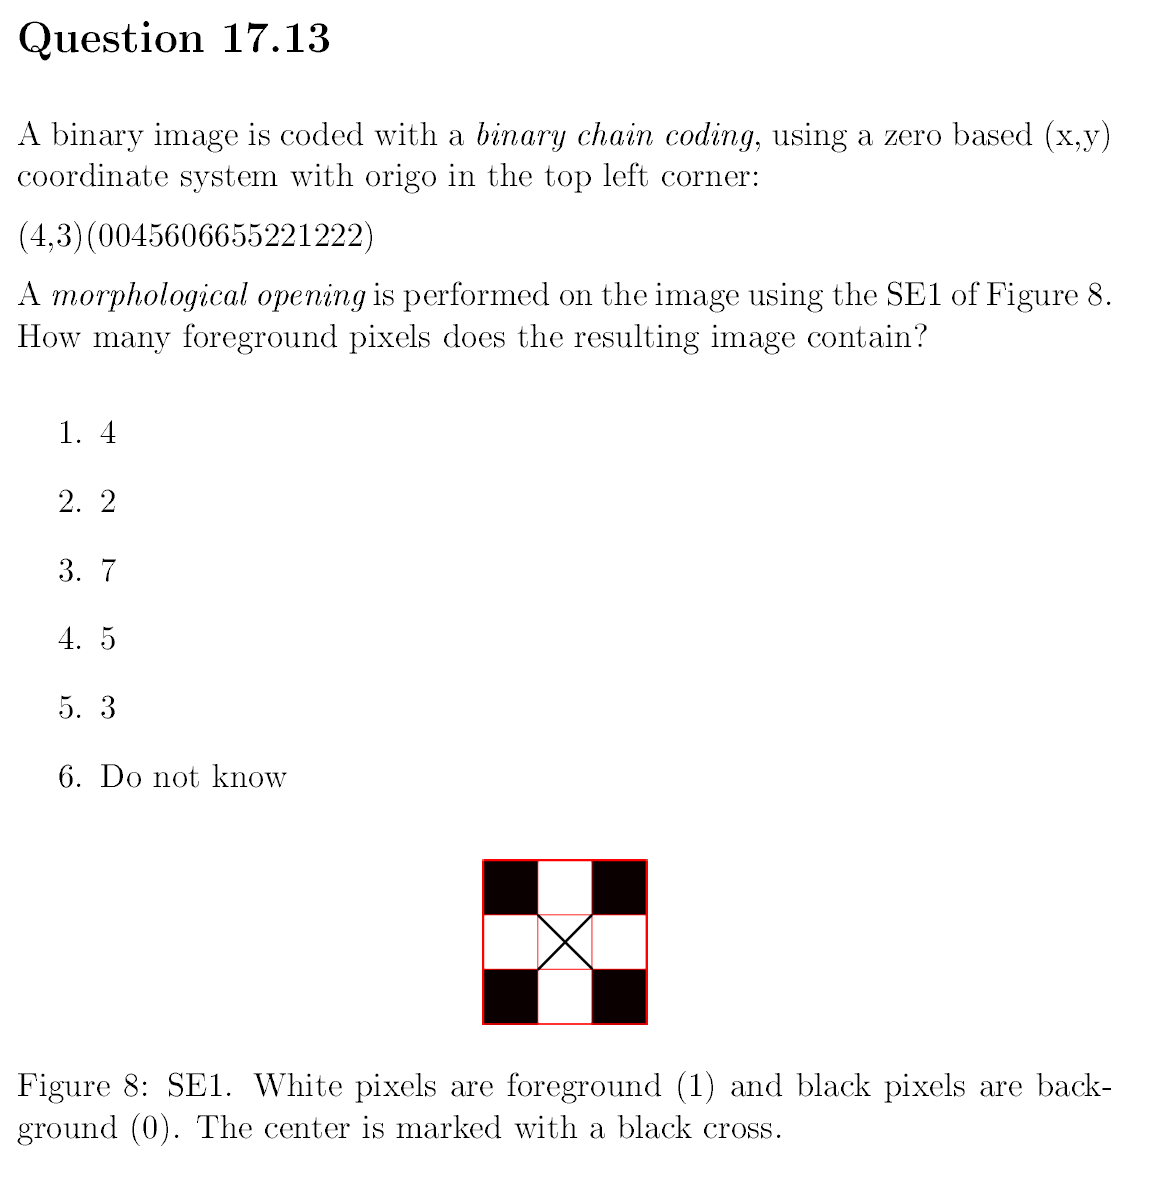

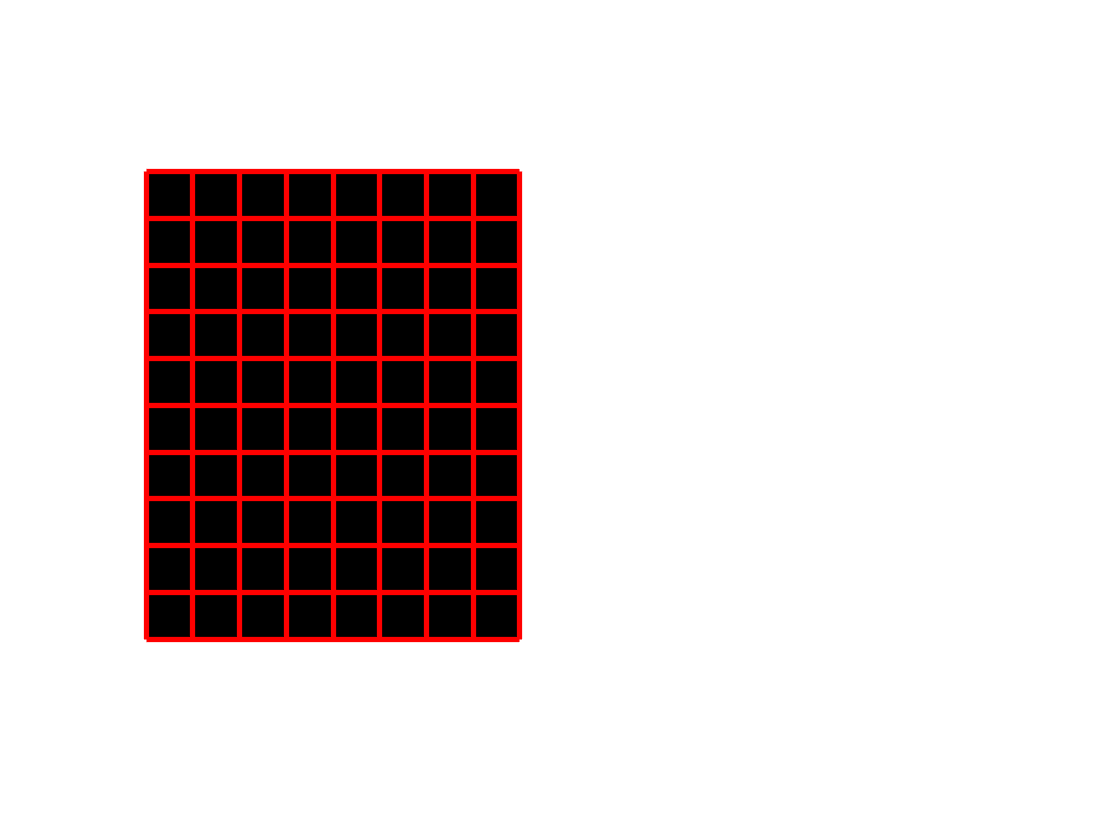

close all; clear; clc;
I = zeros(8);
I(4, 5:7)=1;
I(4:7, 5)=1;
I(6:8,6)=1;
I(8:10,4)=1;
I(9,5)=1;
figure;
subplot(1,2,1)
imshow(I, 'InitialMagnification','fit')
title("no operations")

% the kernels which will be used.
SE1 = strel("disk", 1);
SE2 = strel("square", 3);


%opening = erotion + dilation
I_first = imerode(I, SE1);
I_second = imdilate(I_first, SE1);

exam_funcs.imshow_binary(I)
exam_funcs.imshow_binary(I_second)

sum(I_second, "all")

ans = 0

SVar: ved ikke....

## Q14

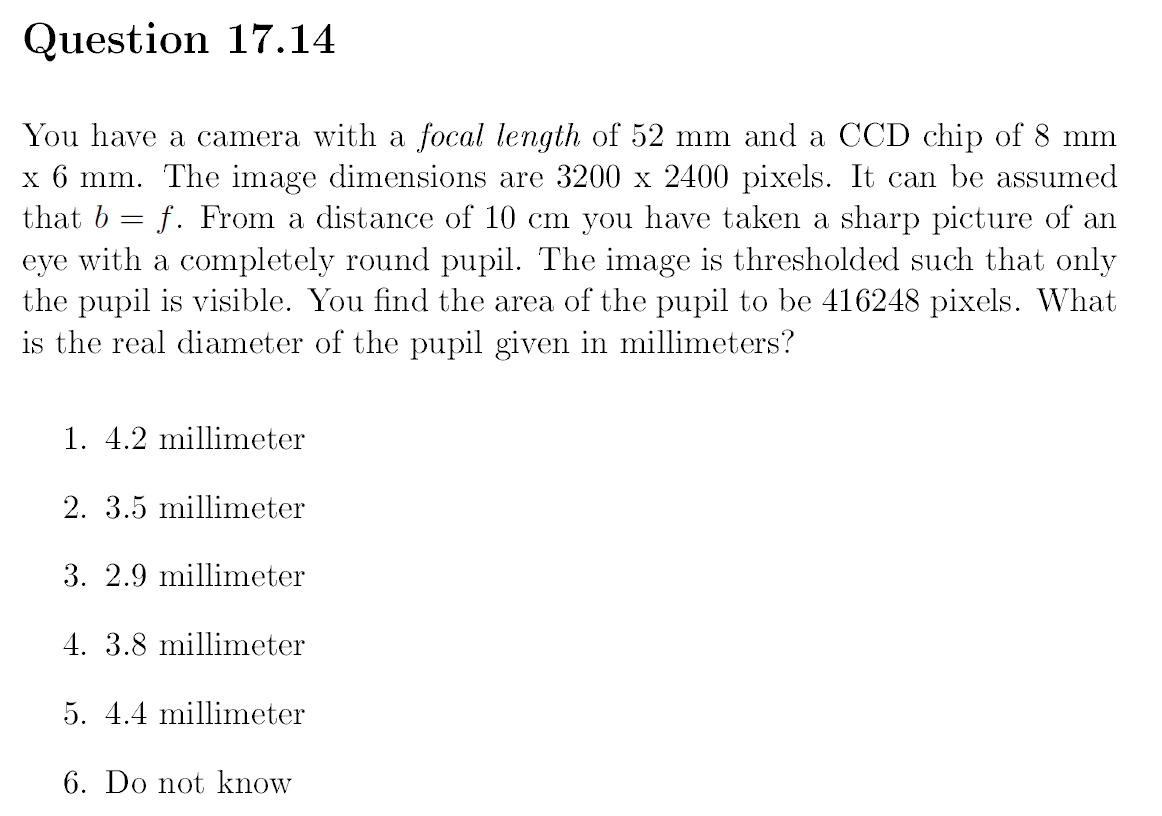

close all; clear; clc;
b = 52;
g = 10*10;
%A = 416248 pixels . Areal af en cirkel er pi*r^2. r = 363.98 pixels 
% diameteren i pixels er 727.96 pixels 

% What is the real diameter of the pupil in millimeters 
%G = ?

B = 727.96 %pixels Diameteren i pixels

%solve
%727.96 = (G/g)*b*3200/8

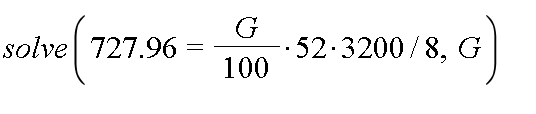

svaret er 2: 3.499807692

## Q15

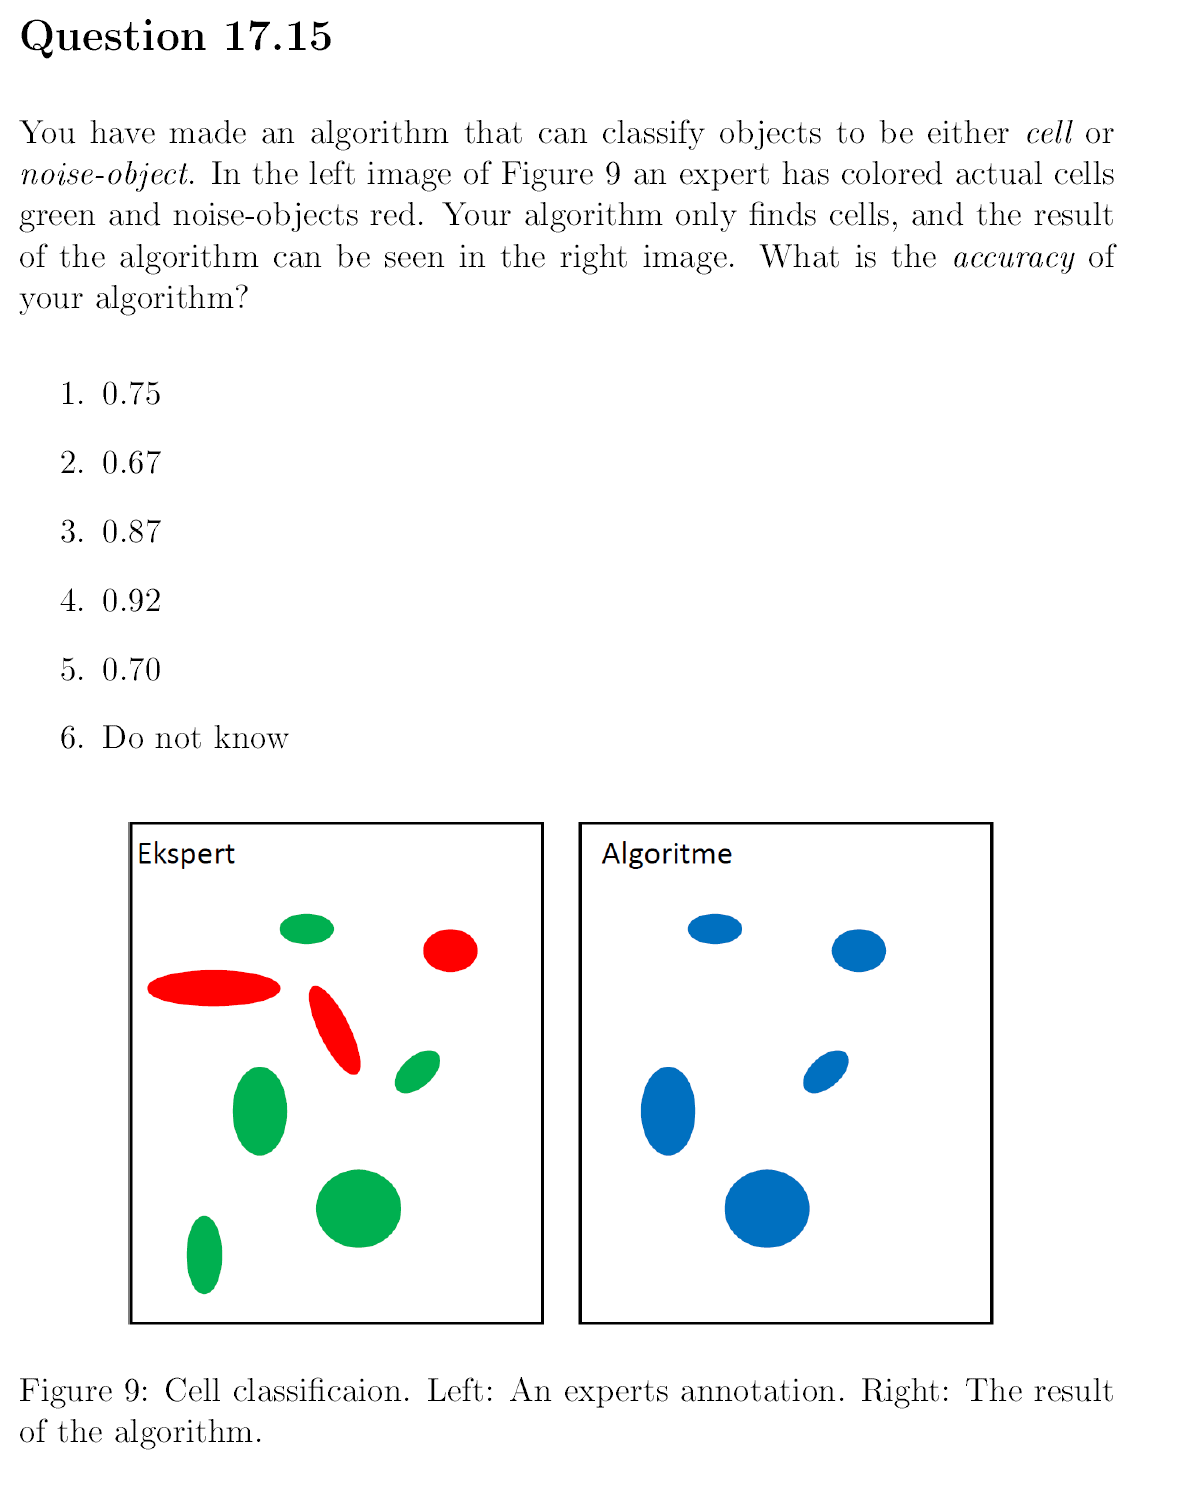

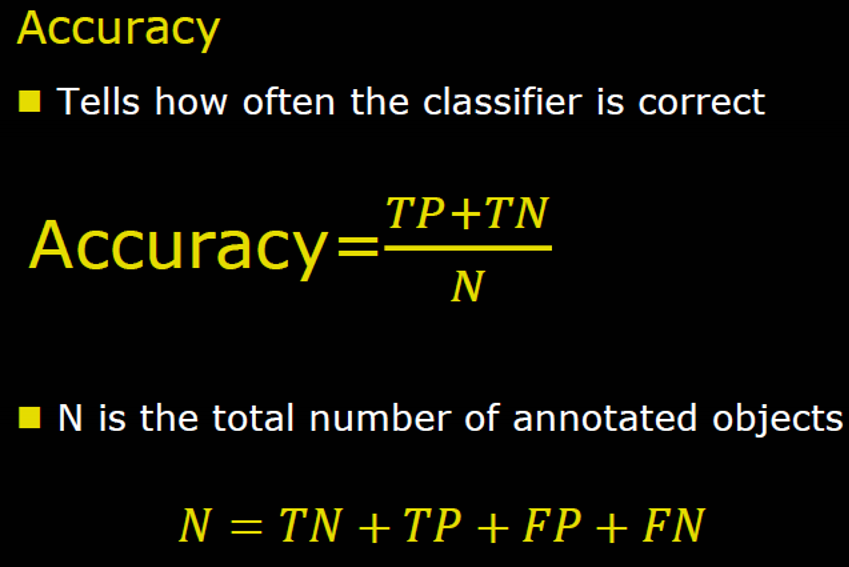

close all; clear; clc;

TP = 4;
TN = 2;
FP = 1;
FN = 1;
N = TP + TN + FP + FN;
acc = (TP+TN)/N

acc = 0.7500

Svaret er1:  0.75

## Q16

close all; clear; clc;
%x,y der skal transformeres
point = [37.4,23.5];

% indskriv mulighederne og transformer igen
for x = [198, 155, 201, 164, 177]
    X = [37 38 37 38];
    Y = [23 23 24 24];
    V = [105 204 232 111];
    BilinearInterpo = exam_funcs.BilinearInterpolation(point,X,Y,V);
    BilinearInterpo
end

BilinearInterpo = 164.1000

BilinearInterpo = 164.1000

BilinearInterpo = 164.1000

BilinearInterpo = 164.1000

BilinearInterpo = 164.1000

Svaret er 4: 164

## Q17 - gray level mapping 

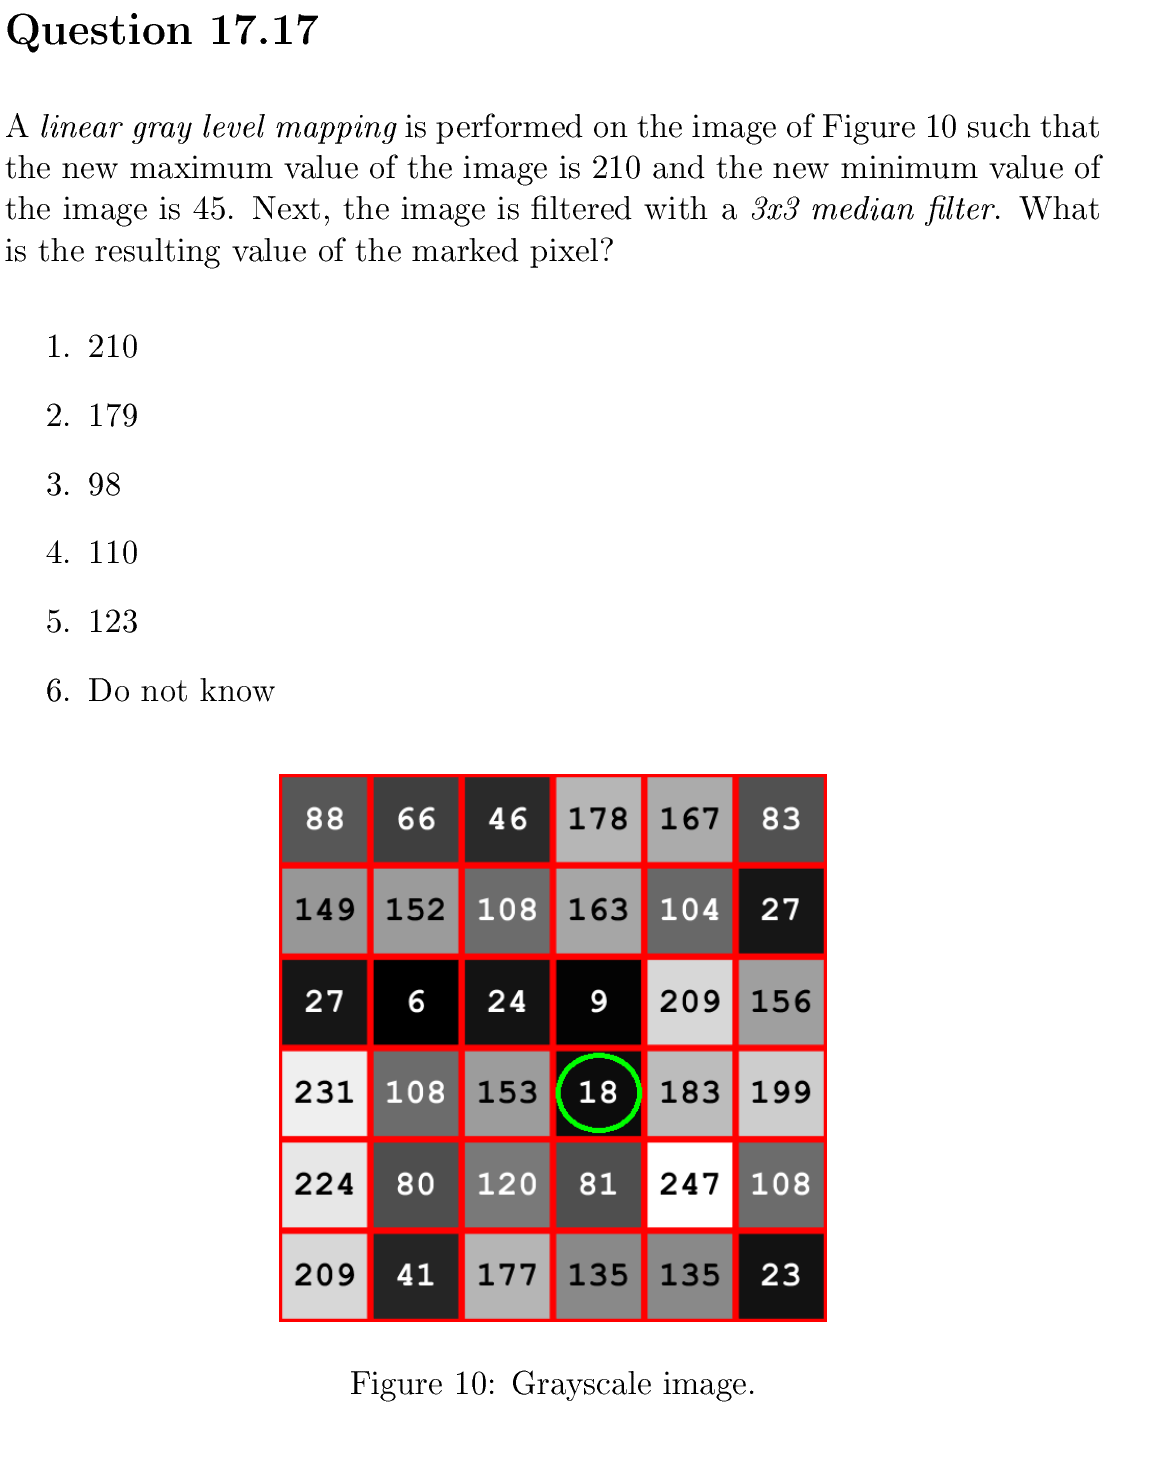

close all; clear; clc;
I = [88, 66, 46, 178, 167, 83;
149, 152, 108, 163, 104, 27;
27, 6, 24, 9, 209, 156;
231, 108, 153, 18, 183, 199;
224, 80, 120, 81, 247, 108;
209, 41, 177, 135, 135, 23];

% A linear gray level mapping is performed
I_map = exam_funcs.GrayMap(I, 45, 210);

% 3 x 3 median filter
I_filt = ordfilt2(I_map, 5, ones(3,3));

% result in the marked pixel
I_filt(4,4)

ans = 123.0498

Svaret er derved 5: 123

## Q18

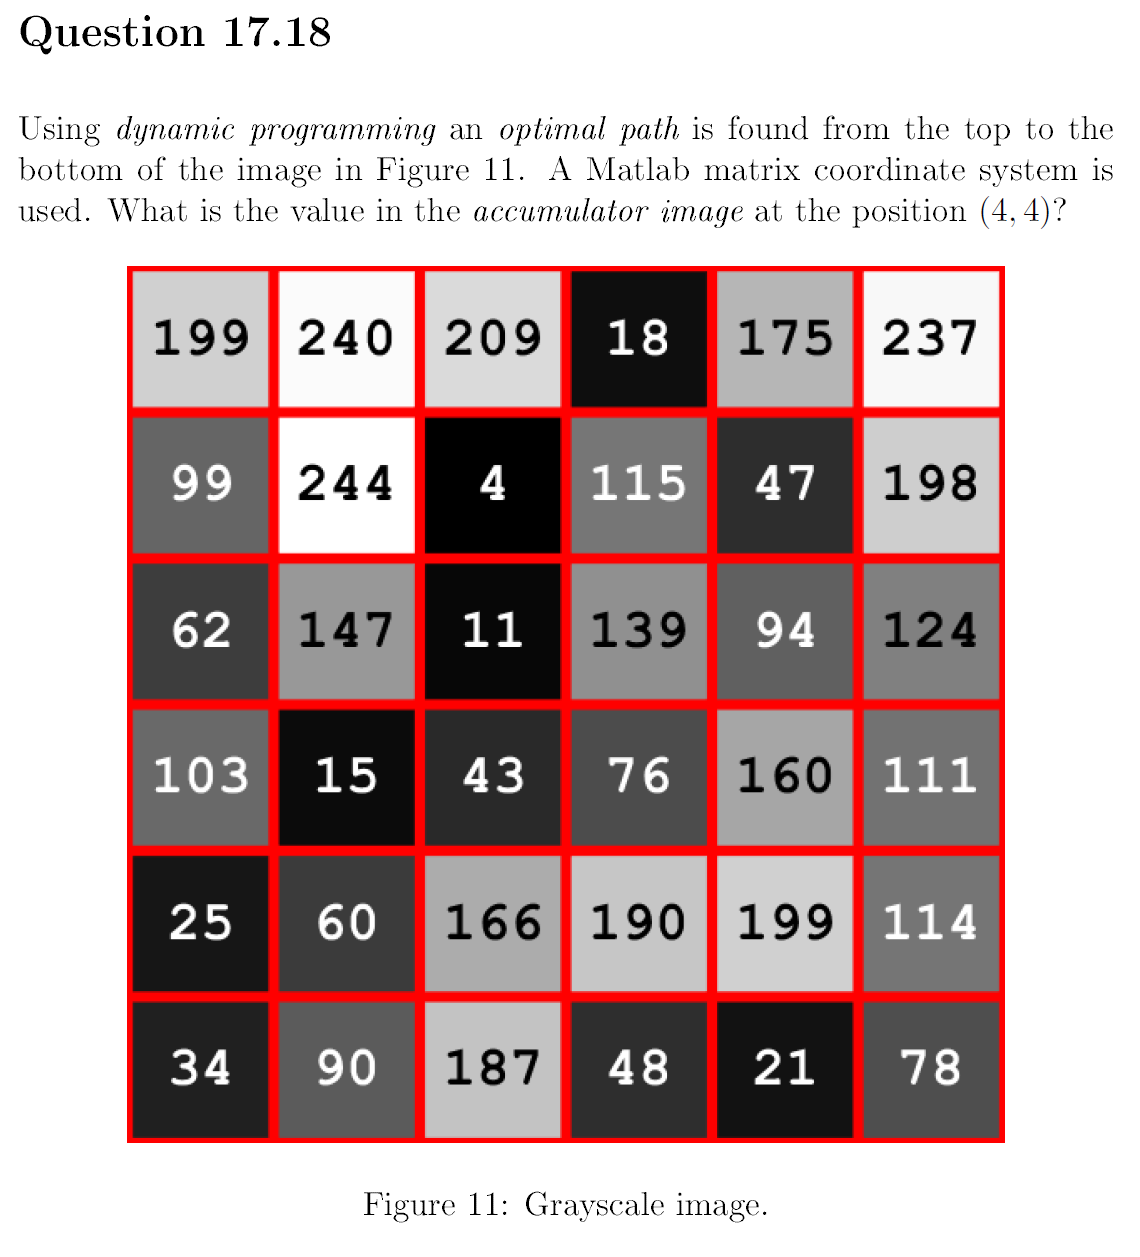

close all; clear; clc;ex = exam_funcs;
I = [199, 240, 209, 18, 175, 237;
99, 244, 4, 115, 47, 198;
62, 147, 11, 139, 94, 124;
103, 15, 43, 76, 160, 111;
25, 60, 166, 190, 199, 114;
34, 90, 187, 48, 21, 78];

I = I(1:4, :); % stating the forth
I

I =    199   240   209    18   175   237
    99   244     4   115    47   198
    62   147    11   139    94   124
   103    15    43    76   160   111


for i = 1:length(I)
    I_tmp = I;
    val = I_tmp(4, i);
    I_tmp(4, i) = 0;
    val + ex.OptPath(I_tmp)
end

ans = 463

ans = 48

ans = 76

ans = 109

ans = 319

ans = 270

Svaret er derved 3: 109

## Q19

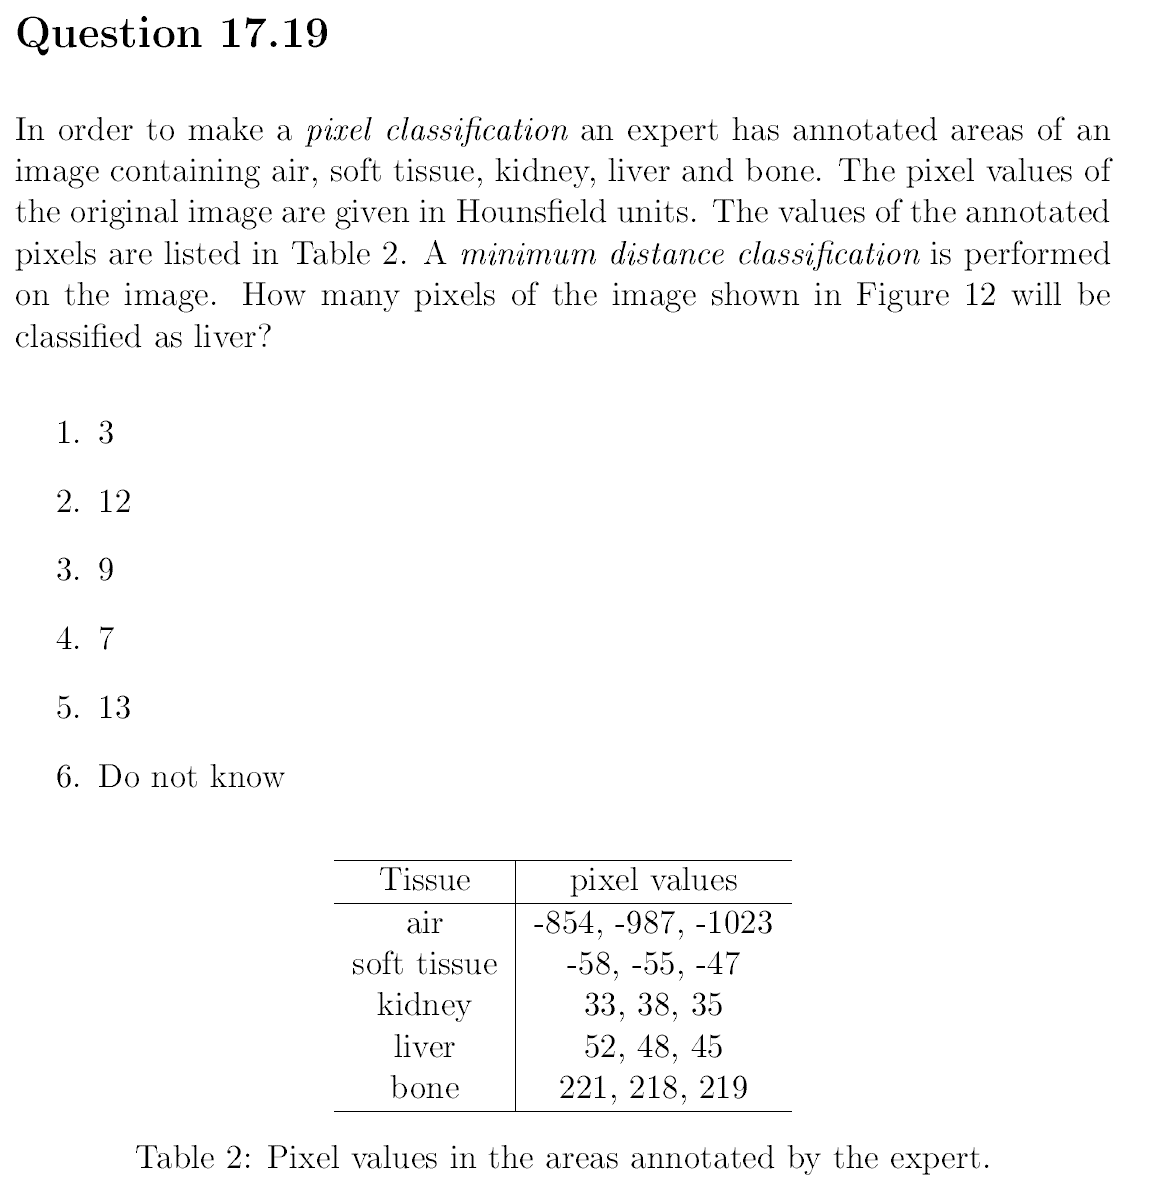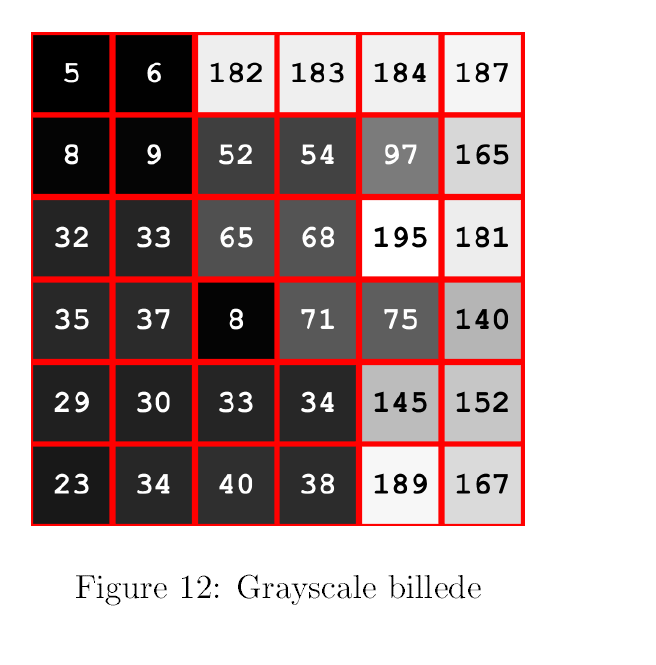

close all; clear; clc;ex = exam_funcs;


I = [5, 6, 182, 183, 184, 187;
8, 9, 52, 54, 97, 165;
32, 33, 65, 68, 195, 181;
35, 37, 8, 71, 75, 140;
29, 30, 33, 34, 145, 152;
23, 34, 40, 38, 189, 167];

% minimum distance classifier
air = [-854, -987, -1023];
soft = [-58, -55, -47];
kidney = [33, 38, 35];
liver = [52, 48, 45];
bone = [221, 218, 219];

% eyebrow, iris , skin er rækkefølgen


%minimum distance classifier and finding the class range 
% her kigger vi på hvad der ligger under og over. Så først alle elementer,
% der er over den nedre grænse og så alle elementer, der er under den øvre
% grænse. 
sum(I > (mean(kidney)+mean(liver))/2      & I < (mean(bone)+mean(liver))/2, "all")

ans = 7

Svaret er 4: 7

## Q20

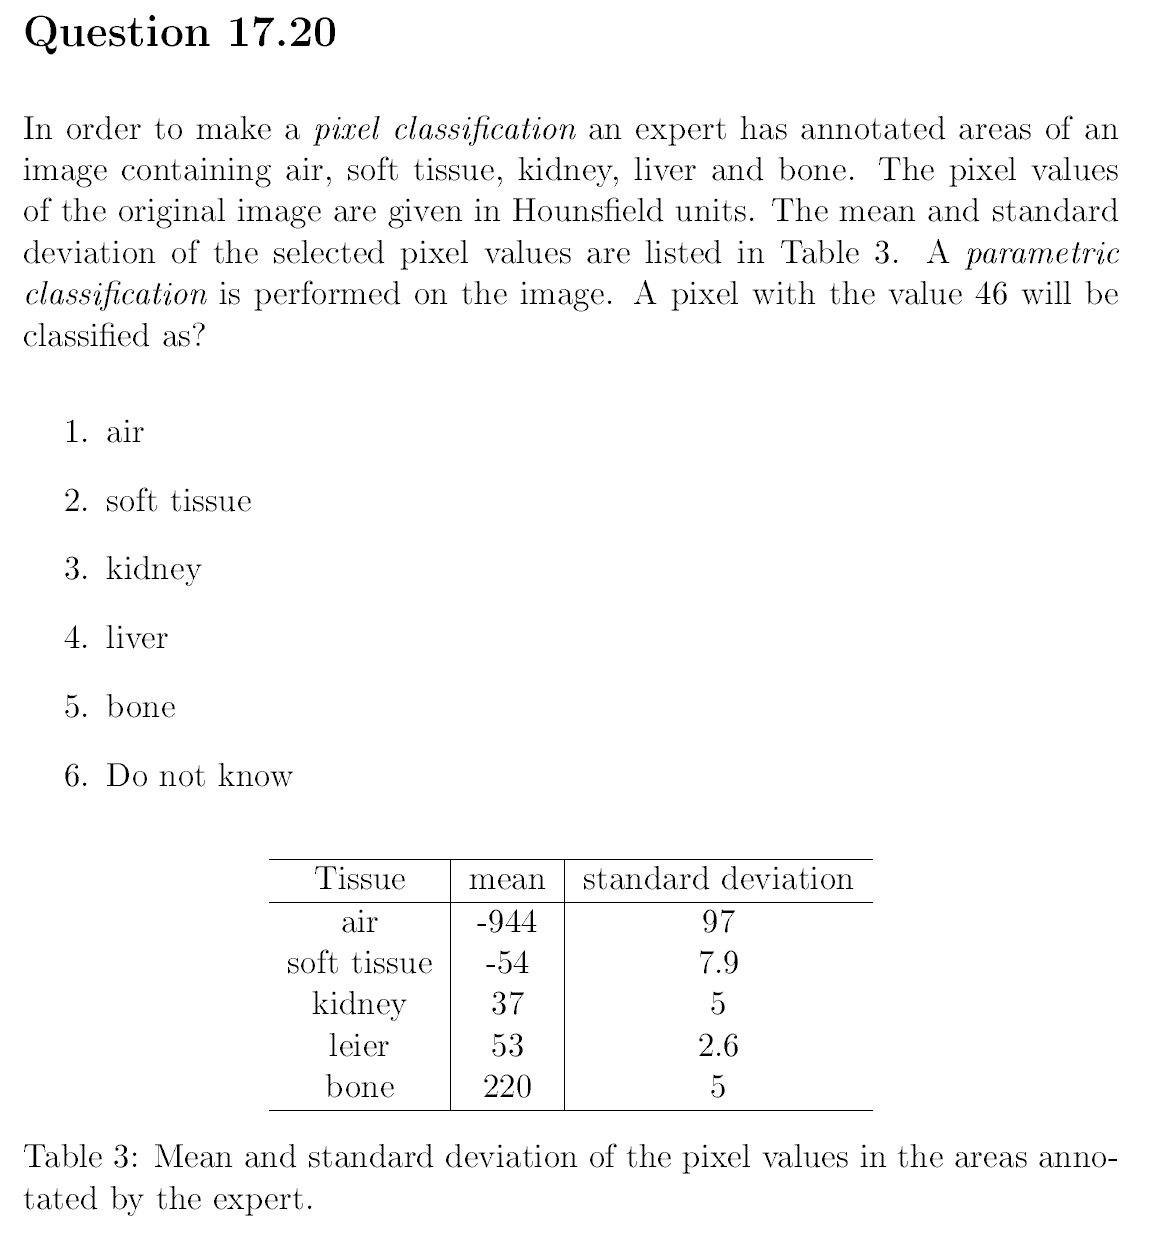

close all; clear; clc;ex = exam_funcs;


I = [5, 6, 182, 183, 184, 187;
8, 9, 52, 54, 97, 165;
32, 33, 65, 68, 195, 181;
35, 37, 8, 71, 75, 140;
29, 30, 33, 34, 145, 152;
23, 34, 40, 38, 189, 167];

% minimum distance classifier
air = [-854, -987, -1023];
soft = [-58, -55, -47];
kidney = [33, 38, 35];
liver = [52, 48, 45];
bone = [221, 218, 219];

x = 46;


% Parametric classification
% look at the probability of x lying within the norm distributions
p_air = normpdf(x, -944, 97)

p_air = 9.8794e-26

p_soft = normpdf(x, -54, 7.9)

p_soft = 8.1212e-37

p_kidney = normpdf(x, 37, 5)

p_kidney = 0.0158

p_liver = normpdf(x, 53, 2.6)

p_liver = 0.0041

p_bone = normpdf(x, 220, 5)

p_bone = 8.4712e-265

Svaret er kidney. 

3. kidney

## Q21

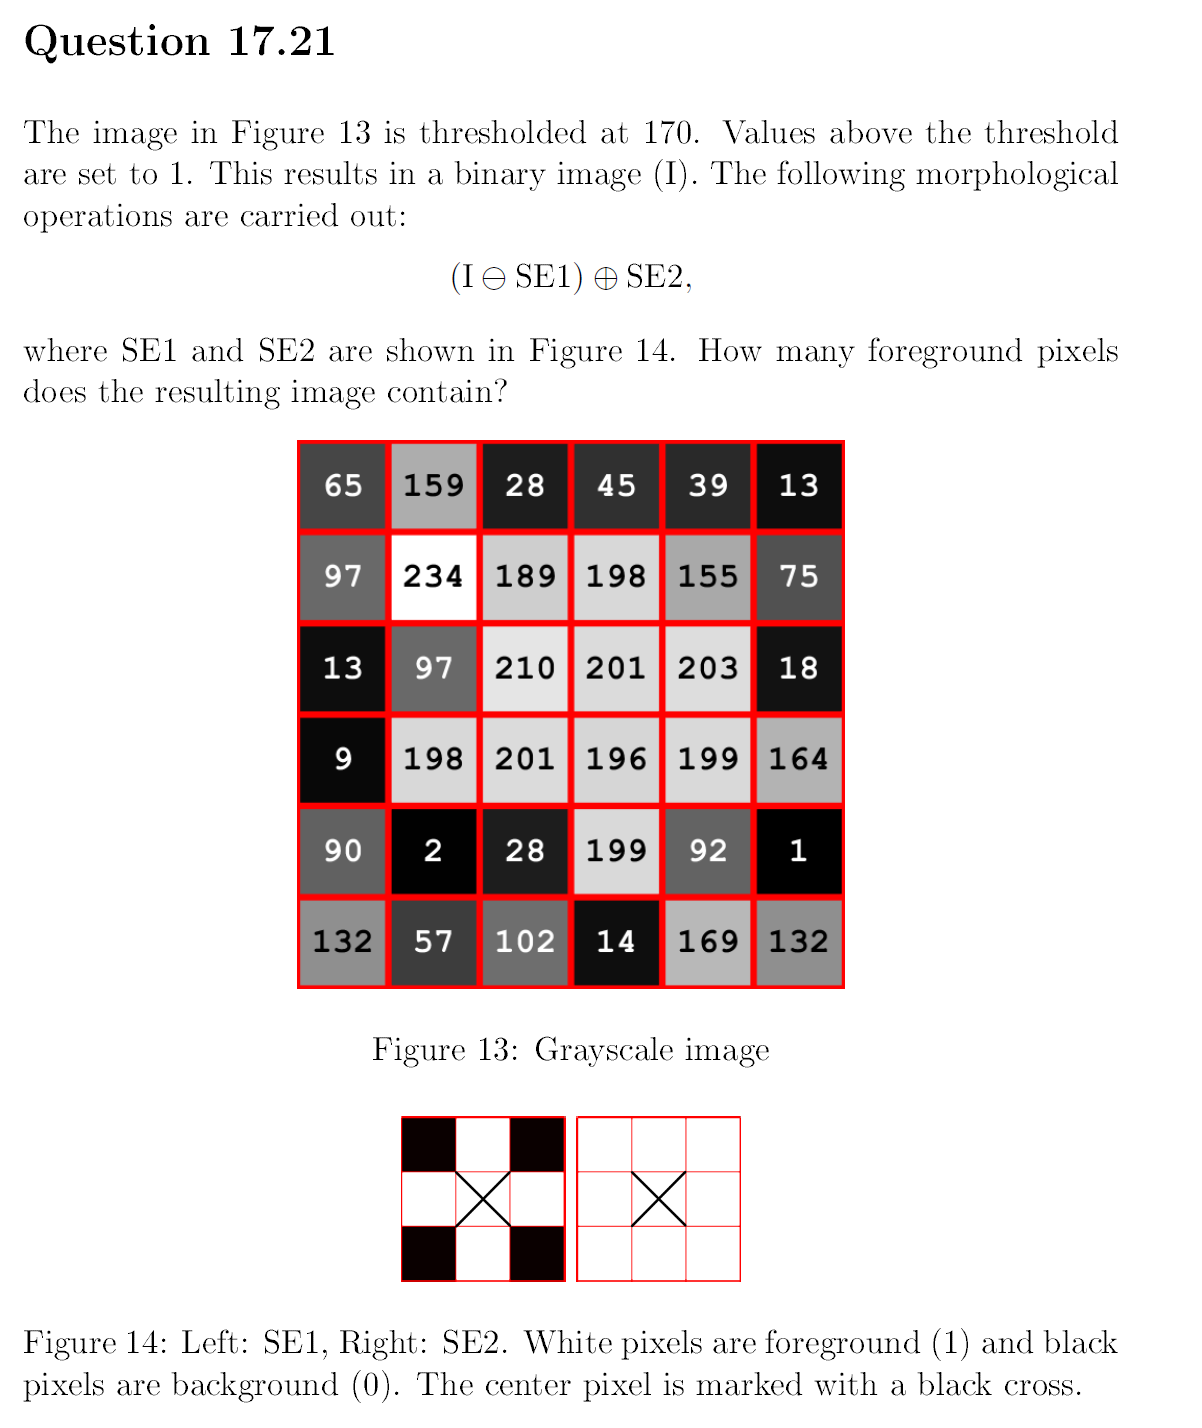

close all; clear; clc;
I = [65, 159, 28, 45, 39, 13;
97, 234, 189, 198, 155, 75;
13, 97, 210, 201, 203, 18;
9, 198, 201, 196, 199, 164;
90, 2, 28, 199, 92, 1;
132, 57, 102, 14, 169, 132];

figure;
subplot(1,2,1)
imshow(I, 'InitialMagnification','fit')
title("no operations")

% the kernels which will be used.
SE1 = strel("disk", 1);
SE2 = strel("square", 3);

% threshold
I = imbinarize(I, 170)

I = 6×6 logical array
   0   0   0   0   0   0
   0   1   1   1   0   0
   0   0   1   1   1   0
   0   1   1   1   1   0
   0   0   0   1   0   0
   0   0   0   0   0   0


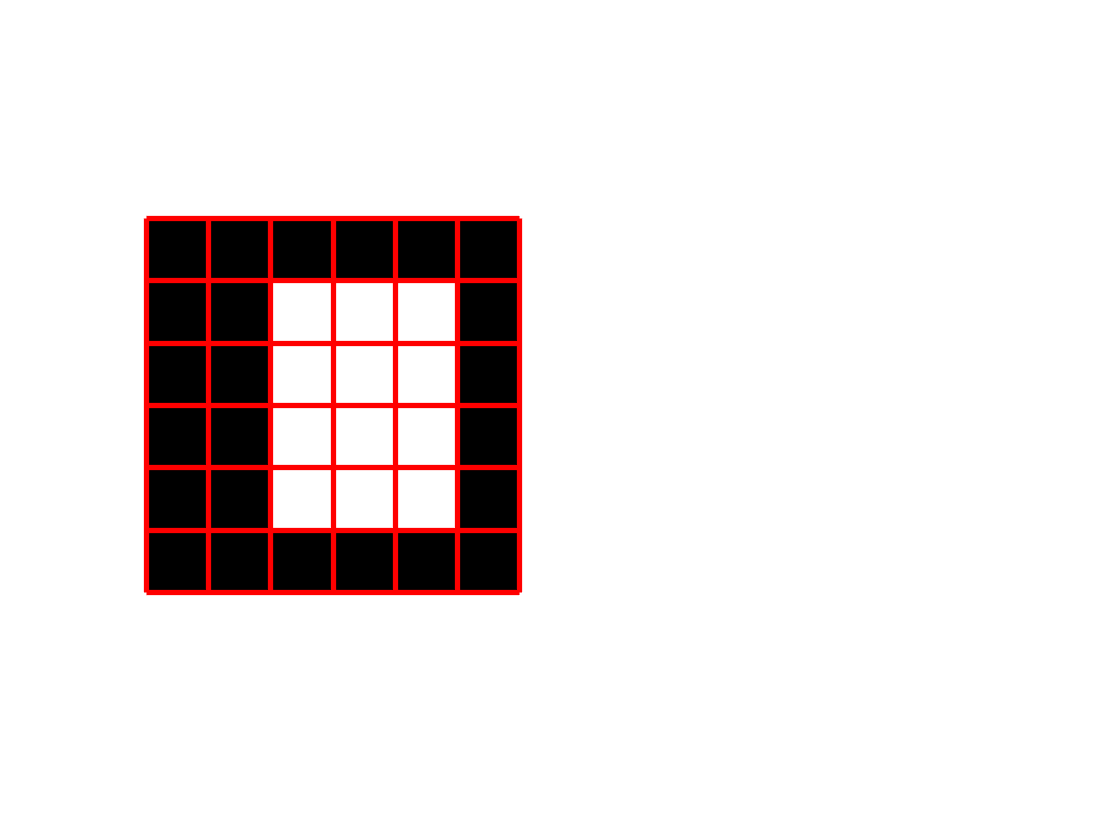


%opening = erotion + dilation
I_first = imerode(I, SE1);
I_second = imdilate(I_first, SE2);

exam_funcs.imshow_binary(I)
exam_funcs.imshow_binary(I_second)

sum(I_second, "all")

ans = 12

Svaret er 2: 12

## Q23

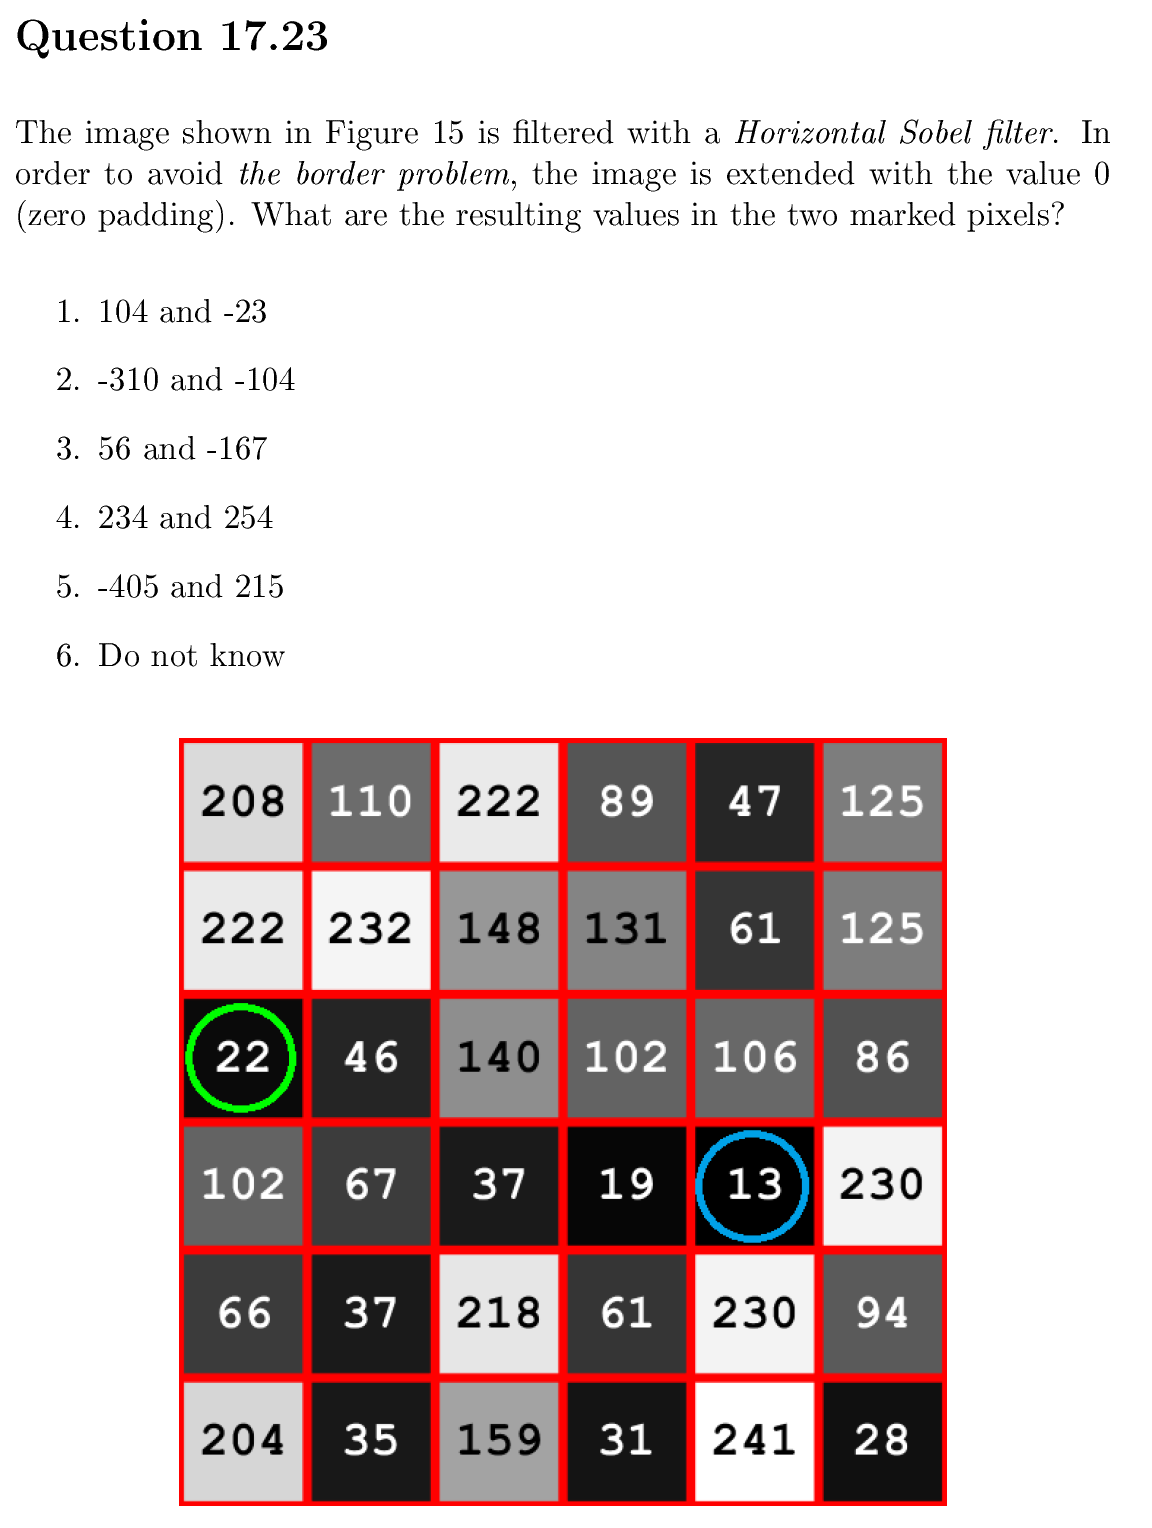

close all; clear; clc;
I = [208, 110, 222, 89, 47, 125;
222, 232, 148, 131, 61, 125;
22, 46, 140, 102, 106, 86;
102, 67, 37, 19, 13, 230;
66, 37, 218, 61, 230, 94;
204, 35, 159, 31, 241, 28];

% horizontal sobel filter
sobel = [-1 0 1; -2 0 2; -1 0 1]';
I_filt = imfilter(I, sobel);
I_filt(3,1)

ans = -405

I_filt(4,5)

ans = 215

ans = 431

ans = 396

ans = 366

ans = 348

ans = 329

ans = 546

Svaret er 5. 

## Q25

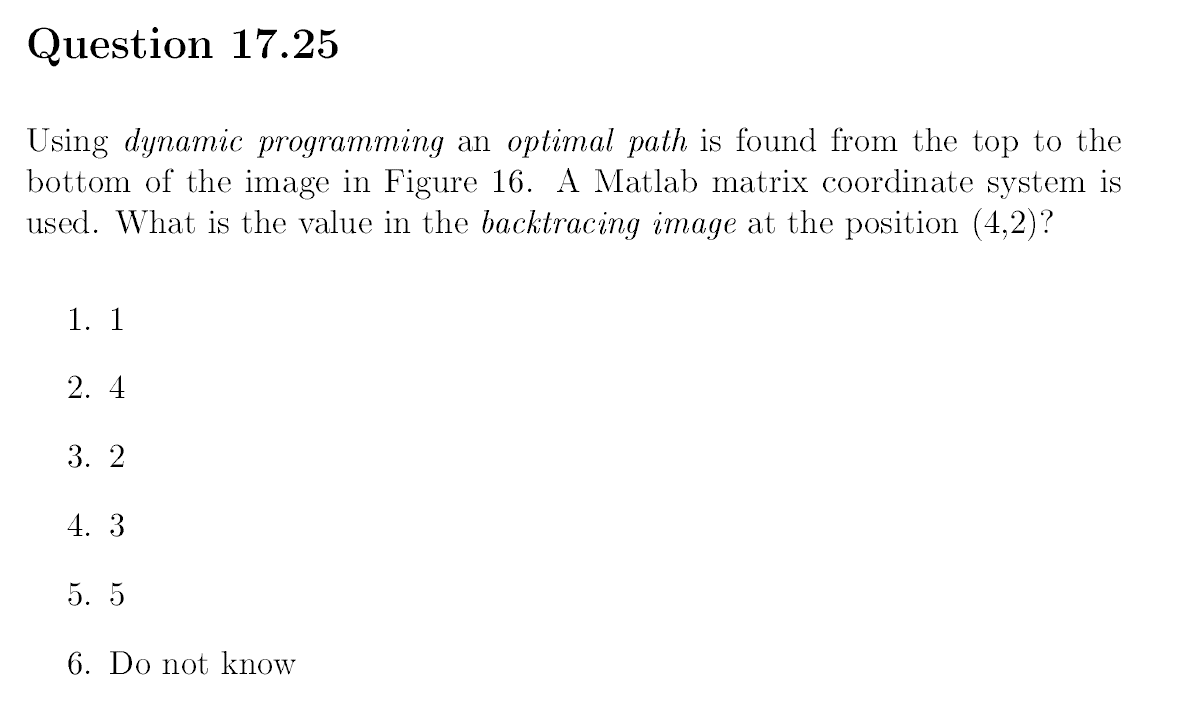

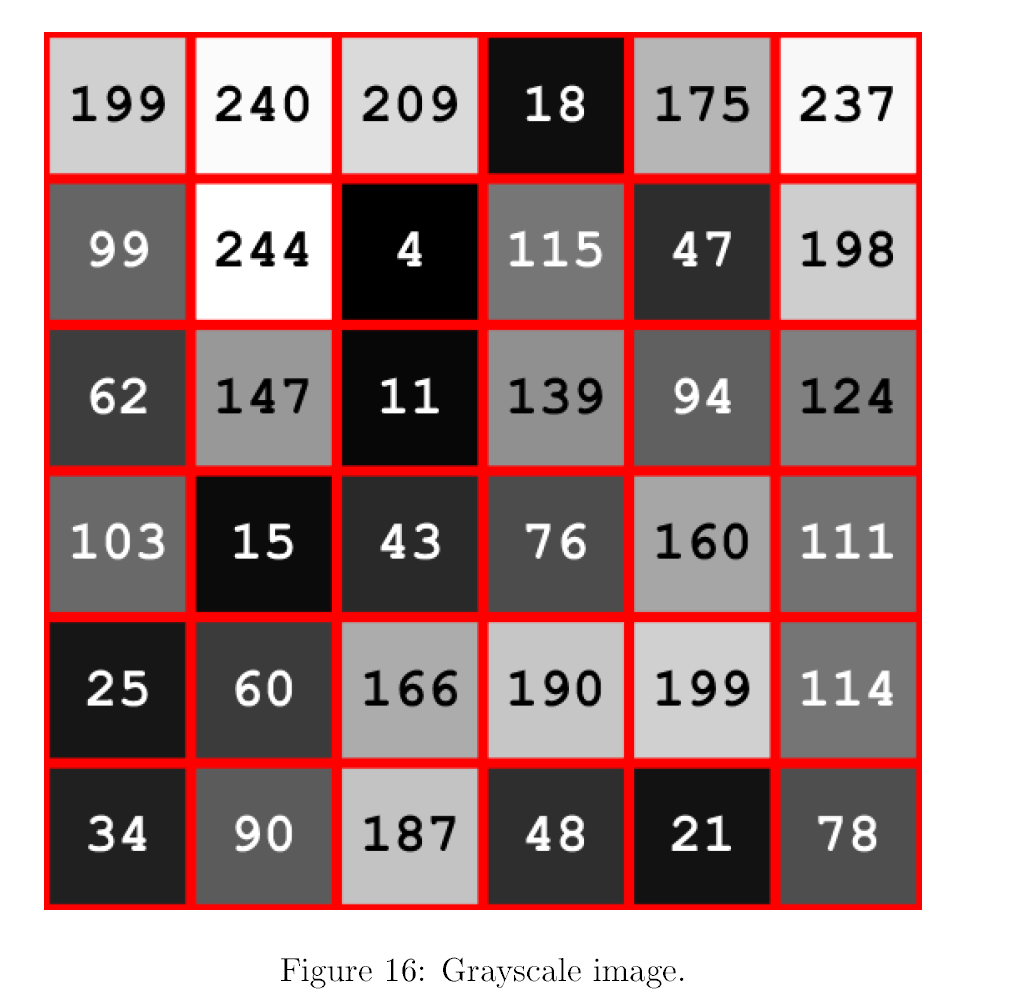

close all; clear; clc;
% Hvis den ender der, så kom den fra column nr. 3 ovenover. 
%derfor er svaret 4. 3

I = [199, 240, 209, 18, 175, 237;
99, 244, 4, 115, 47, 198;
62, 147, 11, 139, 94, 124;
103, 15, 43, 76, 160, 111;
25, 60, 166, 190, 199, 114;
34, 90, 187, 48, 21, 78];
I(4,2)=0;
[~, path] = exam_funcs.OptPath(I);
path

path =      4     5     5     6     6     5


I =    199   240   209    18   175   237
    99   244     4   115    47   198
    62   147    11   139    94   124
   103     0    43    76   160   111
    25    60   166   190   199   114
    34    90   187    48    21    78


path =      4     5     5     6     6     5
